clc; clear; close all;

addpath('D:\UC_Berkeley_study\New_Approach_for_GMPE\Program\VsProfileInversion_Linda');

addpath('D:\UC_Berkeley_study\New_Approach_for_GMPE\Program\function_need');

addpath('D:\UC_Berkeley_study\New_Approach_for_GMPE\Program');

load('EASPSA_NGA_West2_ASK14_Extension.mat');  % this data is new.

%%%%%%%%%%% This data relevant to those used in the BA19 %%%%%%%%%%%%

 df = df(ismember(df.RegionFlag,'California'),:);
 

 df = rmmissing(df);
 
%  df = df(df.ClstD_km_ >= 20,:);
 
 RSN = df.RecordSequenceNumber;
%  writetable(df,'D:\UC_Berkeley_study\New_Approach_for_GMPE\Program\data_\EASPSA_NGA_West2_ASK14_Extension.csv','Delimiter',',','QuoteStrings',true);

 VarNames = df.Properties.VariableNames;
 
 f_eas_hz_loc = VarNames(contains(VarNames,' Hz'));
 
 f_eas_hz = split(f_eas_hz_loc); 
 
 f_eas_hz = str2double(f_eas_hz(:,:,1));
 
% Consider the usable frequency range
  eas_array_flatfile = df(:, f_eas_hz_loc); % eas amplitude 301 values. 

% this is data array of useable eas amplitude. 
  eas_array_useable = table2array(eas_array_flatfile);

% frequencies range used in the BA19.

## Decouble kappa 

eas_array_useable_ = nan(size(eas_array_useable));

for irec = 1:size(eas_array_useable,1)
    
  iLUF = 1.25*max(df.HP_H1_Hz_(irec),df.HP_H2_Hz_(irec));

  iHUF = (1/1.25)*min(df.LP_H1_Hz_(irec),df.LP_H2_Hz_(irec));
  
  if iHUF < iLUF
      iHUF = 20;
  end
  
  ifusable = f_eas_hz >=iLUF & f_eas_hz <= iHUF;
  
  eas_array_useable_(irec,ifusable) = eas_array_useable(irec,ifusable);
  
end

% Remove kappa from the data 
%     del_kappa =  -0.1098 + 0.0184*log(df.Vs30_m_s_SelectedForAnalysis);
%     
%     Q = exp(-pi * del_kappa * f_eas_hz);     
%     
%     eas_array_useable_ = eas_array_useable_.* Q;


## Step - 2: Set up model

fc = 0.1000


Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


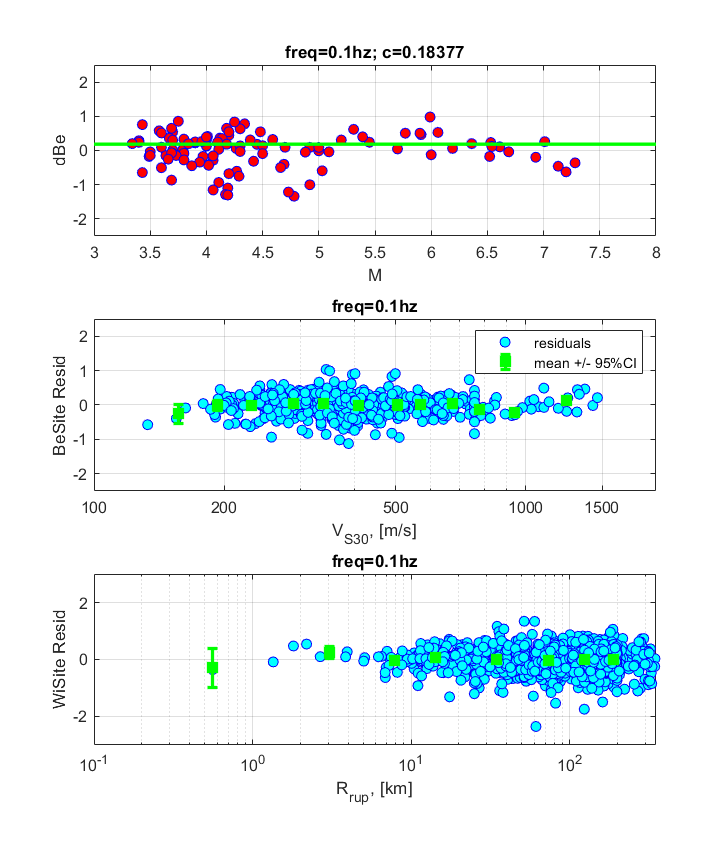

fc = 0.5000


Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


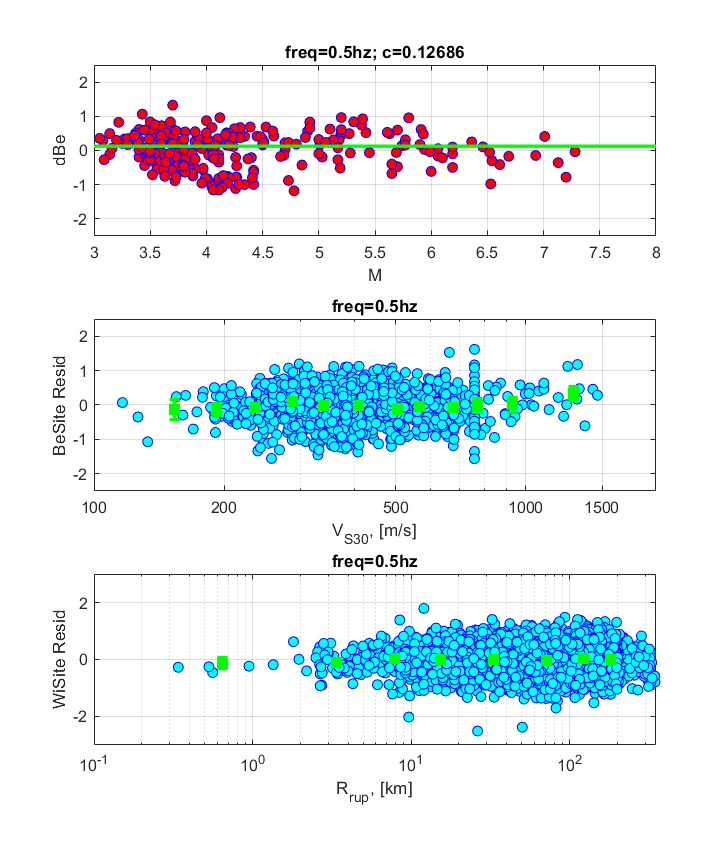

fc = 0.7500


Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


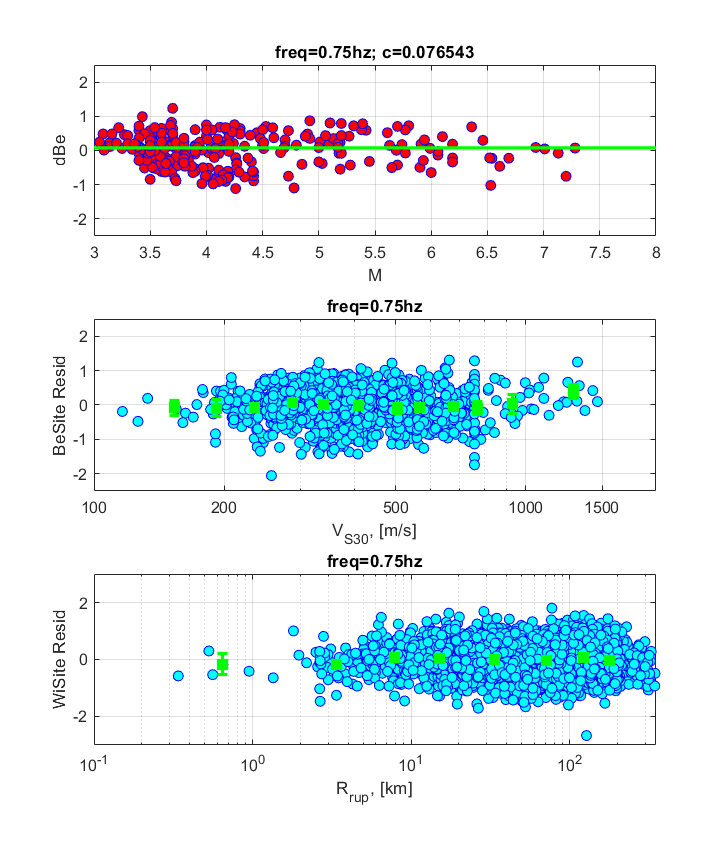

fc = 1


Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


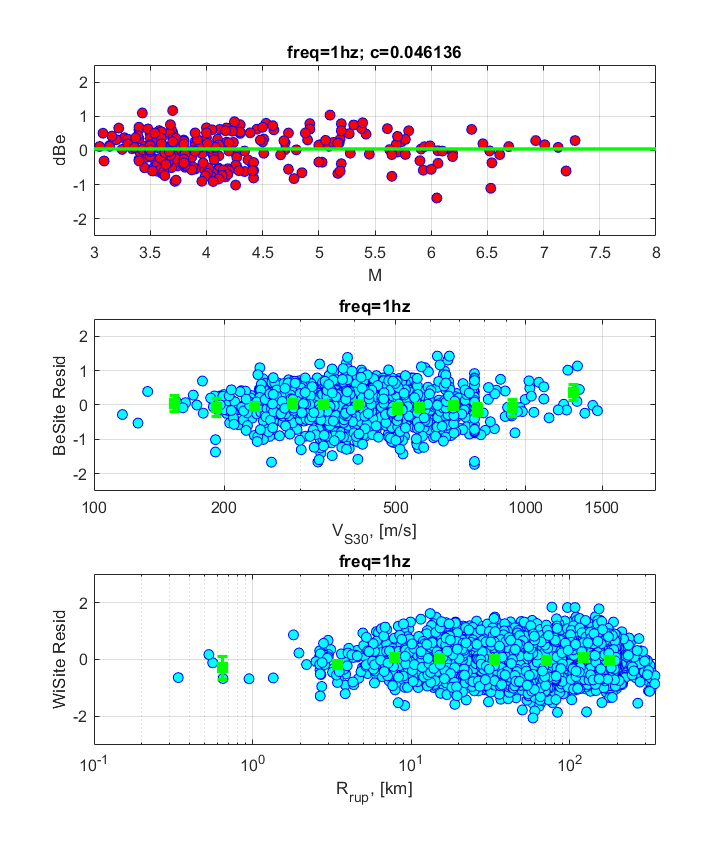

fc = 1.5000


Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


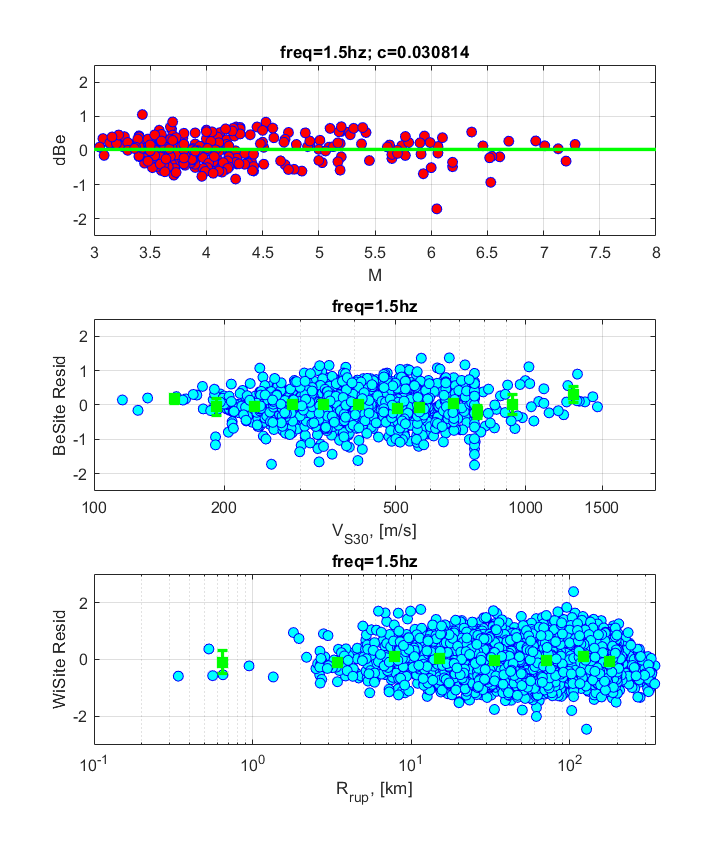

fc = 2


Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


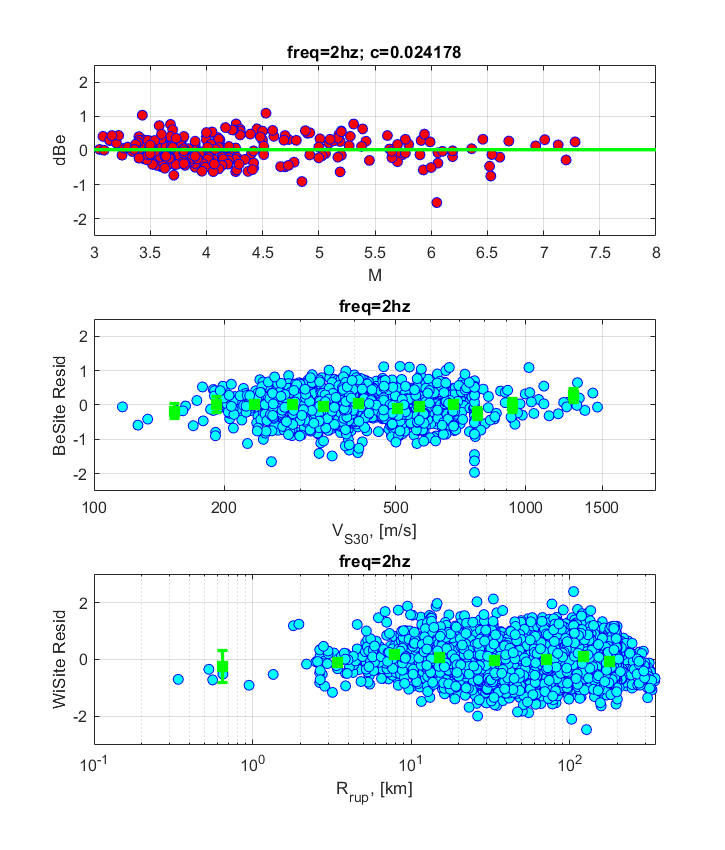

  
ck_array = [];
 
freq = [0.1 0.1023293 0.1047129 0.10715192 0.10964782 0.11220184 0.1148154 0.1174898 0.12022643...
        0.1230269 0.12589254 0.12882494 0.1318257 0.1348963 0.13803841 0.14125373 0.144544 0.14791083 0.15135611 0.1548817 0.15848931 0.162181...
        0.1659587 0.1698244 0.1737801 0.177828 0.1819701 0.18620871 0.1905461 0.19498443 0.1995262 0.2041738 0.20892961 0.2137962 0.2187762...
        0.22387212 0.2290868 0.2344229 0.2398833 0.2454709 0.2511886 0.25703954 0.2630268 0.26915344 0.2754229 0.2818383 0.28840312 0.29512092...
        0.3019952 0.30902954 0.3162278 0.32359364 0.3311311 0.33884412 0.34673681 0.3548134 0.3630781 0.37153521 0.3801894 0.38904511 0.39810714...
        0.4073803 0.4168694 0.42657953 0.4365158 0.4466836 0.4570882 0.4677351 0.4786301 0.48977881 0.5011872 0.51286131 0.5248075 0.5370318...
        0.5495409 0.5623413 0.57543992 0.5888436 0.6025595 0.61659491 0.6309573 0.6456543 0.6606934 0.676083 0.69183093 0.7079458 0.72443592...
        0.74131023 0.7585776 0.7762471 0.79432821 0.81283044 0.8317637 0.8511381 0.8709636 0.8912509 0.9120108 0.93325424 0.9549925 0.9772371...
        1 1.023293 1.047129 1.0715192 1.096478 1.1220182 1.1481534 1.1748973 1.2022641 1.230269 1.258926 1.28825 1.318257 1.348963 1.3803842...
        1.4125374 1.44544 1.4791082 1.513561 1.5488164 1.584893 1.62181 1.659587 1.698244 1.737801 1.7782794 1.819701 1.862087 1.905461 1.9498444...
        1.9952621 2.041738 2.089296 2.137962 2.187761 2.2387211 2.290868 2.344229 2.398833 2.454709 2.5118863 2.570396 2.630268 2.691535 2.7542283...
        2.818383 2.884031 2.951209 3.019952 3.090296 3.162278 3.235937 3.311311 3.3884413 3.4673681 3.548134 3.63078 3.715352 3.8018932 3.890451...
        3.981071 4.073803 4.168694 4.2657952 4.365158 4.4668354 4.5708813 4.677351 4.7863001 4.897787 5.011872 5.128613 5.248074 5.3703184 5.495409...
        5.623413 5.7543992 5.8884363 6.025596 6.1659493 6.309573 6.456542 6.606934 6.7608284 6.9183082 7.0794563 7.24436 7.413103 7.585776 7.762471...
        7.9432821 8.1283044 8.3176364 8.5113792 8.709635 8.912507 9.120107 9.332541 9.549923 9.7723722 10 10.23293 10.471284 10.715192 10.96478...
        11.220183 11.481534 11.748973 12.022642 12.302684 12.589251 12.882492 13.182563 13.489624 13.80384 14.12537 14.454392 14.79108 15.135614...
        15.48817 15.848933 16.218101 16.59587 16.98244 17.37801 17.782793 18.19701 18.62087 19.05461 19.498443 19.952621 20.41738 20.89296 21.37962...
        21.877611 22.38721 22.908672 23.442283 23.988321];    
       
% the para for z2p5: 

%         a6 = [0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	-0.0001	-0.0001	-0.0001	-0.0001	-0.0001	-0.0001	-0.0002	-0.0002	-0.0002	-0.0003	-0.0003	-0.0003	-0.0004	-0.0004	-0.0005	-0.0005	-0.0006	-0.0006	-0.0007	-0.0007	-0.0008	-0.0009	-0.0009	-0.0010	-0.0011	-0.0012	-0.0013	-0.0014	-0.0015	-0.0015	-0.0016	-0.0018	-0.0019	-0.0020	-0.0021	-0.0022	-0.0023	-0.0024	-0.0026	-0.0027	-0.0028	-0.0029	-0.0031	-0.0032	-0.0033	-0.0035	-0.0036	-0.0038	-0.0039	-0.0041	-0.0042	-0.0043	-0.0045	-0.0047	-0.0048	-0.0050	-0.0051	-0.0053	-0.0054	-0.0056	-0.0058	-0.0059	-0.0061	-0.0062	-0.0064	-0.0066	-0.0067	-0.0069	-0.0071	-0.0072	-0.0074	-0.0076	-0.0077	-0.0079	-0.0080	-0.0082	-0.0083	-0.0085	-0.0086	-0.0088	-0.0089	-0.0091	-0.0092	-0.0093	-0.0095	-0.0096	-0.0097	-0.0098	-0.0100	-0.0101	-0.0102	-0.0103	-0.0104	-0.0105	-0.0106	-0.0107	-0.0108	-0.0109	-0.0110	-0.0111	-0.0111	-0.0112	-0.0113	-0.0113	-0.0114	-0.0114	-0.0115	-0.0115	-0.0116	-0.0116	-0.0116	-0.0116	-0.0116	-0.0116	-0.0116	-0.0116	-0.0116	-0.0116	-0.0116	-0.0116	-0.0116	-0.0116	-0.0116	-0.0116	-0.0116	-0.0116	-0.0115	-0.0115	-0.0115	-0.0115	-0.0115	-0.0115	-0.0115	-0.0115	-0.0115	-0.0114	-0.0114	-0.0114	-0.0114	-0.0114	-0.0114];
%         a8 = [-1.0911	-1.0978	-1.1045	-1.1111	-1.1177	-1.1243	-1.1308	-1.1373	-1.1438	-1.1503	-1.1567	-1.1631	-1.1695	-1.1759	-1.1823	-1.1887	-1.1951	-1.2015	-1.2080	-1.2144	-1.2207	-1.2273	-1.2341	-1.2409	-1.2479	-1.2549	-1.2619	-1.2690	-1.2762	-1.2836	-1.2911	-1.2989	-1.3068	-1.3149	-1.3231	-1.3313	-1.3395	-1.3475	-1.3553	-1.3629	-1.3701	-1.3771	-1.3836	-1.3899	-1.3958	-1.4014	-1.4067	-1.4118	-1.4166	-1.4211	-1.4253	-1.4292	-1.4326	-1.4358	-1.4385	-1.4409	-1.4430	-1.4447	-1.4462	-1.4475	-1.4486	-1.4495	-1.4502	-1.4507	-1.4511	-1.4512	-1.4511	-1.4506	-1.4498	-1.4487	-1.4472	-1.4454	-1.4433	-1.4408	-1.4381	-1.4350	-1.4316	-1.4280	-1.4241	-1.4201	-1.4157	-1.4112	-1.4063	-1.4011	-1.3956	-1.3898	-1.3837	-1.3773	-1.3707	-1.3639	-1.3570	-1.3499	-1.3426	-1.3351	-1.3274	-1.3196	-1.3115	-1.3032	-1.2946	-1.2858	-1.2770	-1.2680	-1.2589	-1.2498	-1.2406	-1.2314	-1.2221	-1.2127	-1.2033	-1.1936	-1.1838	-1.1738	-1.1637	-1.1533	-1.1427	-1.1318	-1.1207	-1.1092	-1.0975	-1.0853	-1.0728	-1.0599	-1.0466	-1.0329	-1.0188	-1.0043	-0.9894	-0.9742	-0.9587	-0.9429	-0.9270	-0.9110	-0.8949	-0.8787	-0.8626	-0.8464	-0.8304	-0.8144	-0.7985	-0.7827	-0.7670	-0.7514	-0.7360	-0.7207	-0.7054	-0.6904	-0.6754	-0.6605	-0.6457	-0.6310	-0.6164	-0.6017	-0.5869	-0.5722	-0.5573	-0.5424	-0.5274	-0.5123	-0.4970	-0.4816	-0.4660	-0.4504	-0.4347	-0.4190	-0.4032	-0.3873	-0.3716	-0.3559	-0.3405	-0.3254	-0.3106	-0.2963	-0.2826	-0.2693	-0.2566	-0.2444	-0.2327	-0.2214	-0.2104	-0.1998	-0.1894	-0.1794	-0.1697	-0.1602	-0.1511	-0.1424	-0.1340	-0.1259	-0.1183	-0.1109	-0.1039	-0.0970	-0.0903	-0.0836	-0.0769	-0.0700	-0.0630	-0.0558	-0.0484	-0.0408	-0.0330	-0.0250	-0.0170	-0.0088	-0.0005	0.0079	0.0166	0.0254	0.0344	0.0437	0.0531	0.0628	0.0727	0.0827	0.0929	0.1034	0.1140	0.1248	0.1357	0.1470	0.1583	0.1696	0.1809	0.1923	0.2036	0.2149	0.2261	0.2374	0.2487	0.2600	0.2712	0.2825	0.2938	0.3051	0.3163	0.3276	0.3390	0.3503	0.3616];
%         a9 = [-0.4127	-0.4191	-0.4255	-0.4319	-0.4384	-0.4448	-0.4512	-0.4577	-0.4641	-0.4705	-0.4770	-0.4834	-0.4899	-0.4964	-0.5028	-0.5093	-0.5158	-0.5223	-0.5288	-0.5353	-0.5419	-0.5484	-0.5549	-0.5615	-0.5680	-0.5746	-0.5812	-0.5877	-0.5943	-0.6008	-0.6074	-0.6139	-0.6204	-0.6268	-0.6333	-0.6397	-0.6467	-0.6538	-0.6610	-0.6684	-0.6758	-0.6832	-0.6908	-0.6985	-0.7062	-0.7140	-0.7218	-0.7297	-0.7377	-0.7456	-0.7535	-0.7614	-0.7692	-0.7770	-0.7846	-0.7923	-0.7998	-0.8072	-0.8146	-0.8218	-0.8290	-0.8360	-0.8430	-0.8499	-0.8567	-0.8634	-0.8700	-0.8765	-0.8829	-0.8891	-0.8953	-0.9012	-0.9071	-0.9128	-0.9183	-0.9236	-0.9288	-0.9339	-0.9388	-0.9435	-0.9480	-0.9523	-0.9565	-0.9604	-0.9642	-0.9679	-0.9714	-0.9747	-0.9779	-0.9810	-0.9840	-0.9868	-0.9896	-0.9922	-0.9947	-0.9971	-0.9994	-1.0016	-1.0037	-1.0056	-1.0074	-1.0090	-1.0105	-1.0119	-1.0131	-1.0141	-1.0150	-1.0157	-1.0162	-1.0165	-1.0166	-1.0164	-1.0161	-1.0155	-1.0147	-1.0136	-1.0123	-1.0109	-1.0092	-1.0073	-1.0052	-1.0029	-1.0004	-0.9977	-0.9948	-0.9917	-0.9884	-0.9850	-0.9814	-0.9776	-0.9736	-0.9694	-0.9651	-0.9605	-0.9557	-0.9507	-0.9455	-0.9401	-0.9344	-0.9285	-0.9224	-0.9160	-0.9094	-0.9026	-0.8956	-0.8883	-0.8808	-0.8730	-0.8651	-0.8569	-0.8486	-0.8400	-0.8312	-0.8223	-0.8132	-0.8039	-0.7944	-0.7848	-0.7750	-0.7651	-0.7551	-0.7449	-0.7345	-0.7240	-0.7133	-0.7024	-0.6914	-0.6802	-0.6688	-0.6572	-0.6454	-0.6335	-0.6214	-0.6092	-0.5968	-0.5843	-0.5717	-0.5589	-0.5461	-0.5331	-0.5201	-0.5069	-0.4937	-0.4804	-0.4670	-0.4536	-0.4401	-0.4265	-0.4129	-0.3991	-0.3853	-0.3714	-0.3574	-0.3433	-0.3291	-0.3148	-0.3004	-0.2859	-0.2712	-0.2565	-0.2416	-0.2266	-0.2115	-0.1963	-0.1801	-0.1639	-0.1476	-0.1313	-0.1150	-0.0986	-0.0823	-0.0659	-0.0496	-0.0332	-0.0168	-0.0004	0.0160	0.0325	0.0489	0.0654	0.0819	0.0984	0.1149	0.1314	0.1480	0.1645	0.1811	0.1977	0.2144	0.2310	0.2476	0.2643	0.2810	0.2977	0.3144	0.3312	0.3479	0.3647	0.3815];
	a5  =  [0.1434	0.1387	0.1341	0.1296	0.1251	0.1206	0.1162	0.1118	0.1075	0.1032	0.0990	0.0947	0.0906	0.0864	0.0822	0.0781	0.0740	0.0700	0.0659	0.0619	0.0580	0.0540	0.0502	0.0464	0.0429	0.0398	0.0377	0.0358	0.0341	0.0325	0.0311	0.0298	0.0286	0.0276	0.0268	0.0261	0.0257	0.0254	0.0253	0.0253	0.0256	0.0259	0.0264	0.0270	0.0277	0.0285	0.0293	0.0303	0.0312	0.0322	0.0332	0.0343	0.0355	0.0367	0.0379	0.0392	0.0406	0.0420	0.0435	0.0450	0.0465	0.0480	0.0495	0.0511	0.0526	0.0540	0.0555	0.0569	0.0582	0.0594	0.0605	0.0615	0.0623	0.0630	0.0635	0.0639	0.0642	0.0645	0.0646	0.0647	0.0648	0.0647	0.0646	0.0645	0.0643	0.0641	0.0638	0.0636	0.0634	0.0632	0.0630	0.0629	0.0628	0.0628	0.0629	0.0632	0.0636	0.0641	0.0647	0.0655	0.0665	0.0675	0.0686	0.0699	0.0712	0.0725	0.0739	0.0754	0.0768	0.0783	0.0798	0.0812	0.0827	0.0842	0.0857	0.0871	0.0886	0.0901	0.0916	0.0931	0.0946	0.0960	0.0974	0.0988	0.1000	0.1012	0.1022	0.1031	0.1039	0.1046	0.1052	0.1058	0.1063	0.1067	0.1071	0.1076	0.1081	0.1086	0.1091	0.1097	0.1104	0.1110	0.1117	0.1123	0.1130	0.1136	0.1143	0.1149	0.1155	0.1161	0.1166	0.1171	0.1176	0.1180	0.1185	0.1189	0.1193	0.1198	0.1203	0.1208	0.1213	0.1218	0.1223	0.1227	0.1232	0.1235	0.1238	0.1241	0.1243	0.1245	0.1246	0.1247	0.1248	0.1248	0.1248	0.1247	0.1246	0.1246	0.1244	0.1243	0.1241	0.1239	0.1237	0.1234	0.1231	0.1228	0.1225	0.1222	0.1218	0.1215	0.1212	0.1209	0.1206	0.1203	0.1201	0.1199	0.1198	0.1196	0.1195	0.1195	0.1195	0.1195	0.1196	0.1196	0.1197	0.1197	0.1198	0.1198	0.1199	0.1199	0.1199	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200	0.1200];
        a6     =   [0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	0.0000	-0.0001	-0.0001	-0.0001	-0.0001	-0.0001	-0.0002	-0.0002	-0.0002	-0.0003	-0.0003	-0.0004	-0.0004	-0.0005	-0.0005	-0.0006	-0.0006	-0.0007	-0.0008	-0.0009	-0.0010	-0.0010	-0.0011	-0.0012	-0.0013	-0.0014	-0.0016	-0.0017	-0.0018	-0.0019	-0.0020	-0.0021	-0.0023	-0.0024	-0.0025	-0.0027	-0.0028	-0.0029	-0.0031	-0.0032	-0.0034	-0.0035	-0.0037	-0.0038	-0.0040	-0.0042	-0.0043	-0.0045	-0.0046	-0.0048	-0.0049	-0.0051	-0.0053	-0.0054	-0.0056	-0.0058	-0.0060	-0.0061	-0.0063	-0.0065	-0.0066	-0.0068	-0.0070	-0.0072	-0.0073	-0.0075	-0.0077	-0.0078	-0.0080	-0.0082	-0.0083	-0.0085	-0.0086	-0.0088	-0.0089	-0.0090	-0.0092	-0.0093	-0.0095	-0.0096	-0.0097	-0.0098	-0.0100	-0.0101	-0.0102	-0.0103	-0.0104	-0.0105	-0.0106	-0.0107	-0.0108	-0.0108	-0.0109	-0.0110	-0.0111	-0.0111	-0.0112	-0.0113	-0.0113	-0.0114	-0.0114	-0.0115	-0.0115	-0.0115	-0.0115	-0.0116	-0.0116	-0.0116	-0.0116	-0.0116	-0.0115	-0.0115	-0.0115	-0.0114	-0.0114	-0.0114	-0.0114	-0.0113	-0.0113	-0.0113	-0.0112	-0.0112	-0.0112	-0.0111	-0.0111	-0.0110	-0.0110	-0.0110	-0.0109	-0.0109	-0.0109	-0.0108	-0.0108	-0.0107];
        a8	= [-1.3023	-1.3027	-1.3031	-1.3035	-1.3039	-1.3042	-1.3046	-1.3050	-1.3053	-1.3056	-1.3060	-1.3063	-1.3066	-1.3069	-1.3071	-1.3074	-1.3077	-1.3079	-1.3081	-1.3083	-1.3085	-1.3087	-1.3089	-1.3090	-1.3091	-1.3092	-1.3093	-1.3094	-1.3094	-1.3095	-1.3095	-1.3095	-1.3094	-1.3094	-1.3093	-1.3092	-1.3091	-1.3089	-1.3088	-1.3086	-1.3084	-1.3082	-1.3080	-1.3077	-1.3075	-1.3072	-1.3070	-1.3067	-1.3064	-1.3061	-1.3057	-1.3041	-1.3024	-1.3006	-1.2986	-1.2966	-1.2943	-1.2920	-1.2895	-1.2868	-1.2839	-1.2809	-1.2777	-1.2743	-1.2707	-1.2669	-1.2629	-1.2587	-1.2542	-1.2495	-1.2445	-1.2394	-1.2340	-1.2284	-1.2226	-1.2167	-1.2105	-1.2042	-1.1978	-1.1911	-1.1843	-1.1774	-1.1703	-1.1631	-1.1557	-1.1481	-1.1404	-1.1326	-1.1247	-1.1166	-1.1083	-1.0999	-1.0914	-1.0827	-1.0739	-1.0649	-1.0558	-1.0465	-1.0371	-1.0276	-1.0178	-1.0080	-0.9980	-0.9878	-0.9775	-0.9670	-0.9564	-0.9457	-0.9348	-0.9238	-0.9126	-0.9013	-0.8900	-0.8785	-0.8669	-0.8552	-0.8435	-0.8317	-0.8199	-0.8081	-0.7962	-0.7844	-0.7725	-0.7607	-0.7489	-0.7371	-0.7253	-0.7135	-0.7018	-0.6900	-0.6782	-0.6664	-0.6546	-0.6428	-0.6309	-0.6191	-0.6073	-0.5954	-0.5836	-0.5717	-0.5598	-0.5479	-0.5361	-0.5242	-0.5124	-0.5006	-0.4888	-0.4770	-0.4653	-0.4537	-0.4421	-0.4306	-0.4192	-0.4080	-0.3968	-0.3858	-0.3749	-0.3642	-0.3537	-0.3433	-0.3332	-0.3232	-0.3134	-0.3039	-0.2946	-0.2854	-0.2765	-0.2678	-0.2592	-0.2508	-0.2426	-0.2345	-0.2266	-0.2187	-0.2110	-0.2034	-0.1959	-0.1885	-0.1812	-0.1740	-0.1668	-0.1597	-0.1526	-0.1456	-0.1386	-0.1317	-0.1248	-0.1180	-0.1112	-0.1051	-0.0990	-0.0930	-0.0869	-0.0808	-0.0747	-0.0687	-0.0626	-0.0566	-0.0505	-0.0445	-0.0385	-0.0325	-0.0265	-0.0205	-0.0145	-0.0086	-0.0026	0.0033	0.0092	0.0151	0.0210	0.0269	0.0328	0.0386	0.0445	0.0503	0.0562	0.0620	0.0678	0.0736	0.0794	0.0852	0.0910	0.0968	0.1026	0.1084	0.1141	0.1199	0.1257	0.1314	0.1372	0.1430	0.1487	0.1545	0.1602	0.1660	0.1717	0.1774	0.1832];
        a9	= [-0.3000	-0.3103	-0.3205	-0.3307	-0.3409	-0.3511	-0.3613	-0.3714	-0.3816	-0.3917	-0.4019	-0.4120	-0.4221	-0.4322	-0.4423	-0.4524	-0.4626	-0.4727	-0.4828	-0.4929	-0.5030	-0.5132	-0.5233	-0.5334	-0.5436	-0.5538	-0.5639	-0.5741	-0.5843	-0.5945	-0.6047	-0.6149	-0.6251	-0.6354	-0.6456	-0.6558	-0.6660	-0.6763	-0.6865	-0.6967	-0.7068	-0.7170	-0.7271	-0.7372	-0.7472	-0.7572	-0.7671	-0.7768	-0.7864	-0.7958	-0.8050	-0.8139	-0.8226	-0.8312	-0.8396	-0.8480	-0.8563	-0.8644	-0.8726	-0.8806	-0.8886	-0.8966	-0.9045	-0.9125	-0.9204	-0.9282	-0.9361	-0.9439	-0.9516	-0.9594	-0.9670	-0.9746	-0.9821	-0.9894	-0.9966	-1.0037	-1.0107	-1.0174	-1.0240	-1.0304	-1.0366	-1.0426	-1.0484	-1.0540	-1.0593	-1.0644	-1.0693	-1.0739	-1.0783	-1.0825	-1.0864	-1.0901	-1.0936	-1.0968	-1.0998	-1.1025	-1.1049	-1.1071	-1.1091	-1.1109	-1.1124	-1.1136	-1.1147	-1.1155	-1.1162	-1.1166	-1.1169	-1.1170	-1.1168	-1.1165	-1.1161	-1.1154	-1.1145	-1.1135	-1.1123	-1.1109	-1.1092	-1.1074	-1.1054	-1.1031	-1.1006	-1.0978	-1.0948	-1.0916	-1.0881	-1.0843	-1.0803	-1.0760	-1.0714	-1.0666	-1.0615	-1.0562	-1.0505	-1.0447	-1.0385	-1.0321	-1.0254	-1.0184	-1.0112	-1.0037	-0.9960	-0.9880	-0.9798	-0.9714	-0.9627	-0.9538	-0.9448	-0.9355	-0.9260	-0.9163	-0.9065	-0.8964	-0.8862	-0.8758	-0.8652	-0.8545	-0.8435	-0.8325	-0.8212	-0.8098	-0.7982	-0.7865	-0.7746	-0.7625	-0.7503	-0.7379	-0.7254	-0.7127	-0.6999	-0.6869	-0.6738	-0.6605	-0.6471	-0.6336	-0.6199	-0.6061	-0.5922	-0.5781	-0.5639	-0.5495	-0.5350	-0.5204	-0.5056	-0.4908	-0.4758	-0.4607	-0.4455	-0.4302	-0.4148	-0.3987	-0.3824	-0.3660	-0.3496	-0.3331	-0.3165	-0.3000	-0.2834	-0.2669	-0.2503	-0.2337	-0.2172	-0.2006	-0.1840	-0.1674	-0.1508	-0.1342	-0.1176	-0.1010	-0.0844	-0.0678	-0.0511	-0.0345	-0.0178	-0.0012	0.0155	0.0322	0.0489	0.0656	0.0823	0.0990	0.1158	0.1325	0.1493	0.1661	0.1829	0.1998	0.2166	0.2335	0.2504	0.2673	0.2842	0.3011	0.3181	0.3350	0.3520	0.3690	0.3861	0.4031	0.4202];


        plt = 'y';
     
     if strcmp(plt,'y')
   
       freg = [0.1 0.5 0.75 1 1.5 2];
        fig = figure('Position',[30 30 1080 620]);
     else
        freg = freq;
     end
    
     
     
    for fc = freg
          
      fc
      
      if strcmp(plt,'y')==1
         ik = find(freg ==fc);
         [~, id] = min(abs(f_eas_hz - fc));
         

         it = find(f_eas_hz == f_eas_hz(id));
         ip = find(freq==f_eas_hz(id));
         
      else
          it = find(f_eas_hz == fc); 
          ip = find(freq==fc);
      end
      
      ydata = eas_array_useable_(:,it);
      
      % Remove the row having nan value.
      irm = ~isnan(ydata);
      
      ydata = ydata(irm);
      
      ds = df(irm,:);
      
      EQID = ds.EQID;
      
      STAID = ds.StationSequenceNumber;
      
     %  REGID = ds.RegionFlag;
      
      mag = ds.EarthquakeMagnitude;
      
      rrup = ds.ClstD_km_;
      
      Vs30 = ds.Vs30_m_s_SelectedForAnalysis;
      
      Ztor = ds.DepthToTopOfFaultRuptureModel;


%       [IDQ, ia] = unique(ds.EQID(idx));
%       mc = mag(idx);
%       
%       Mx = mc(ia);
%       
       %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    
       ypred = nan(length(mag),1);
       for k = 1:length(mag)
            ypred(k,1) = Simple_EAS_GMMv8ca(mag(k),rrup(k),Vs30(k),Ztor(k),fc,[]);
            % ypred(k,1)  = BaylessAbrahamson2018_EAS_function(mag(k),rrup(k),Vs30(k),Ztor(k),0,-1,fc);
       end

       fm1 = (mag - 6);
       fm2 = (8.5 - mag).^2;
       fD1 = log(rrup + 5);
       fD2 = a6(ip)*(mag - 6).*log(rrup + 5);
       fD3 = a6(ip)*rrup;
       fZ = min(Ztor/20,1);
       % flreg = ones(length(mag),1).*(~ismember(REGID,'California'));

       fS1 =  a8(ip)*log(min(Vs30,360)/1000);
       
       fS2 =  a9(ip)*log(max(Vs30,360)/1000);
       
  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%     
        Res = log(ydata) - log(ypred);
        
        tb = table(Res, EQID, STAID, fm1,fm2,fD1,fD2,fD3,fZ,fS1,fS2, 'VariableNames',...
                   {'Res','EQID','STAID','fm1','fm2','fD1','fD2','fD3','fZ','fS1','fS2'});
     
        % lme = fitlme(tb,'Res ~ 1  + fm1 + fm2 + fD1 +  fZ +  (1|EQID) + (1|STAID)'); 

        lme = fitlme(tb,'Res ~ 1  +  (1|EQID) + (1|STAID)'); 
        
        ck = fixedEffects(lme); 
        
        [random, Bnames] = randomEffects(lme); 
    
        dBe = random(ismember(Bnames.Group,'EQID'));
        
        dS2S = random(ismember(Bnames.Group,'STAID'));
        
        [~, ib] = unique(STAID);
        
        Wes = residuals(lme);   
        
        tau = std(dBe(abs(dBe) <= 3.75*std(dBe)));
        
        phiSS = std(Wes(abs(Wes) <= 4*std(Wes)));
        
        phiS2S = std(dS2S(abs(dS2S) <= 3.75*std(dS2S)));

         opt = optimset('Algorithm', 'levenberg-marquardt');
         
         ck_array = [ck_array [tau; phiSS; phiS2S; ck]];
        

         
          if strcmp(plt,'y') 
             
%              
            [~, ia] = unique(EQID);
            
            idg = discretize(Vs30(ib),[50 180 200 260 320 360 490 520 630 760 860 1000 2500]);
            
            meanfunc = @(x, y)[exp(mean(log(x))) mean(y) 1.96*std(y)/sqrt(numel(y))];
            
            outdata = splitapply(meanfunc,Vs30(ib),dS2S,idg);
            
            
           
            myfun = @(a,xdata)a(1)*log(xdata) + a(2)*log(xdata).^2;
            beta = lsqcurvefit(myfun, [0.02 -0.35 -0.35] , Vs30(ib), dS2S, [], [], opt);
            ilm = mag(ia)>=5.0 & mag(ia)<=7;
            c = mean(dBe(ilm));
            
            fig = figure('Position',[30 30 580 680]);
            subplot(3,1,1)
            plot(mag(ia),dBe,'bo','MarkerFaceColor','r'); hold on;
            plot([3 8],[c c],'g','LineWidth',2);
            xlabel('M'); ylabel('dBe'); grid on;
            axis([3 8 -2.5 2.5]);
            title(['freq=',num2str(fc),'hz; c=',num2str(c)]);
            
            % subplot(2,2,ik)
            subplot(3,1,2)
            s= semilogx(Vs30(ib), dS2S,'bo','MarkerFaceColor','c'); hold on;
            e= errorbar(outdata(:,1),outdata(:,2),outdata(:,3),'grsq','MarkerFaceColor','gr'); e.LineWidth = 2;
            % b= semilogx(Vs30(ib),myfun(beta,Vs30(ib)),'c.'); hold on;
            % p= semilogx(x,f3D_fun(cita,x),'b-','LineWidth',2); hold on;
            
            if ip==1 
                legend([s,e],'residuals','mean +/- 95%CI');
            end
            
            xlabel('V_{S30}, [m/s]'); 
            ylabel('BeSite Resid'); grid on;
            axis([100 2000 -2.5 2.5]); 
            set(gca,'Xtick',[100, 200, 500, 1000, 1500]);
            title(['freq=',num2str(fc),'hz']);
            
            
            idg = discretize(rrup,[0 2 5 10 20 50 100 150 500]);
            outdata = splitapply(meanfunc,rrup,Wes,idg);
            
            
            subplot(3,1,3)
            semilogx(rrup,Wes,'bo','MarkerFaceColor','c'); hold on;
            e= errorbar(outdata(:,1),outdata(:,2),outdata(:,3),'grsq','MarkerFaceColor','gr'); e.LineWidth = 2;
            xlabel('R_{rup}, [km]'); grid on
            ylabel('WiSite Resid');
            title(['freq=',num2str(fc),'hz']);
            axis([0.1 350 -3.0 3.0]);
            
%             fig_name = strcat('f_',num2str(fc),'hz_Resids.jpg');
%             saveas (fig, ['D:\UC_Berkeley_study\New_Approach_for_GMPE\Program\figures_resid\',fig_name]);  

 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%             m = 3:1:8;
%             idm = discretize(mag,3:1:8);
%             myfunc = @(x,y) [exp(mean(log(x))) mean(y) 1.96*std(y)/sqrt(length(y))];
% 
%             
%             fig1 = figure('Position',[20 20 680 1020]);
%             for i = 1:5
%                 id = find(idm==i);
%                 Vstep = logspace(log10(min(Vs30(id))),log10(max(Vs30(id))),6);
%                 idG = discretize(Vs30(id),Vstep);
%                 Err = splitapply(myfunc,Vs30(id),Wes(id),idG);
%       
%             
%                 subplot(3,2,i)
%                 semilogx(Vs30(id), Wes(id),'o'); hold on;
%                 e = errorbar(Err(:,1),Err(:,2),Err(:,3),'sq');
%                 e.CapSize = 16; e.Color='r'; e.LineWidth = 1.2;
%                 xlabel('V_{S30}, [m/s]'); ylabel('WiEvent-Resid');
%                 axis([100 2500 -2.0 2.0]); grid on;
%                 set(gca,'xtick',[0.1 1 10 100 300]);
%                 set(gca,'ytick',-2.5:0.5:2.5);
%                 title(['f=',num2str(fc),'hz; ','m=',num2str(m(i)),'-',num2str(m(i+1))]);
%     
%             end
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%             m = 3:1:8;
%             idm = discretize(mag,3:1:8);
%             myfunc = @(x,y) [exp(mean(log(x))) mean(y) 1.96*std(y)/sqrt(length(y))];
% 
%             
%             fig2 = figure('Position',[20 20 680 1020]);
%             for i = 1:5
%                 id = find(idm==i);
%                 Rstep = logspace(log10(min(rrup(id))),log10(max(rrup(id))),6);
%                 idG = discretize(rrup(id),Rstep);
%                 Err = splitapply(myfunc,rrup(id),Wes(id),idG);
%       
%             
%                 subplot(3,2,i)
%                 semilogx(rrup(id), Wes(id),'o'); hold on;
%                 e = errorbar(Err(:,1),Err(:,2),Err(:,3),'sq');
%                 e.CapSize = 16; e.Color='r'; e.LineWidth = 1.2;
%                 xlabel('R_{rup}, [km]'); ylabel('WiEvent-Resid');
%                 axis([0.1 500 -2.0 2.0]); grid on;
%                 set(gca,'xtick',[0.1 1 10 100 300]);
%                 set(gca,'ytick',-2.5:0.5:2.5);
%                 title(['f=',num2str(fc),'hz; ','m=',num2str(m(i)),'-',num2str(m(i+1))]);
%     
%             end
%             
          end 
        
    end 

## Comparison Coefficients 

% model developed using extended EAS.
% m0.a7 = [-0.6615	-0.6690	-0.6765	-0.6839	-0.6914	-0.6988	-0.7062	-0.7136	-0.7210	-0.7284	-0.7358	-0.7432	-0.7506	-0.7580	-0.7654	-0.7728	-0.7803	-0.7878	-0.7953	-0.8028	-0.8103	-0.8178	-0.8253	-0.8328	-0.8402	-0.8475	-0.8548	-0.8620	-0.8691	-0.8762	-0.8832	-0.8902	-0.8971	-0.9040	-0.9109	-0.9179	-0.9249	-0.9321	-0.9394	-0.9468	-0.9544	-0.9621	-0.9698	-0.9775	-0.9853	-0.9930	-1.0006	-1.0081	-1.0155	-1.0227	-1.0298	-1.0367	-1.0435	-1.0502	-1.0568	-1.0633	-1.0697	-1.0760	-1.0822	-1.0883	-1.0942	-1.0999	-1.1055	-1.1110	-1.1162	-1.1213	-1.1261	-1.1308	-1.1352	-1.1394	-1.1432	-1.1468	-1.1501	-1.1530	-1.1556	-1.1578	-1.1598	-1.1615	-1.1629	-1.1641	-1.1650	-1.1658	-1.1665	-1.1670	-1.1673	-1.1676	-1.1677	-1.1677	-1.1675	-1.1672	-1.1668	-1.1661	-1.1653	-1.1644	-1.1634	-1.1622	-1.1609	-1.1596	-1.1581	-1.1565	-1.1548	-1.1530	-1.1510	-1.1489	-1.1466	-1.1441	-1.1415	-1.1388	-1.1359	-1.1328	-1.1295	-1.1260	-1.1223	-1.1184	-1.1141	-1.1096	-1.1048	-1.0996	-1.0942	-1.0884	-1.0823	-1.0758	-1.0691	-1.0620	-1.0547	-1.0471	-1.0394	-1.0314	-1.0233	-1.0150	-1.0065	-0.9980	-0.9893	-0.9805	-0.9716	-0.9626	-0.9536	-0.9444	-0.9352	-0.9258	-0.9163	-0.9067	-0.8970	-0.8871	-0.8770	-0.8668	-0.8563	-0.8458	-0.8350	-0.8242	-0.8131	-0.8020	-0.7908	-0.7794	-0.7679	-0.7563	-0.7445	-0.7325	-0.7202	-0.7078	-0.6951	-0.6822	-0.6690	-0.6556	-0.6421	-0.6284	-0.6147	-0.6010	-0.5872	-0.5735	-0.5598	-0.5462	-0.5326	-0.5191	-0.5057	-0.4924	-0.4791	-0.4660	-0.4530	-0.4401	-0.4274	-0.4148	-0.4023	-0.3899	-0.3777	-0.3655	-0.3534	-0.3414	-0.3295	-0.3176	-0.3057	-0.2938	-0.2819	-0.2699	-0.2579	-0.2458	-0.2335	-0.2211	-0.2086	-0.1958	-0.1828	-0.1696	-0.1562	-0.1426	-0.1288	-0.1148	-0.1007	-0.0865	-0.0722	-0.0579	-0.0434	-0.0288	-0.0140	0.0009	0.0166	0.0323	0.0481	0.0639	0.0796	0.0954	0.1112	0.1270	0.1428	0.1586	0.1745	0.1903	0.2062	0.2220	0.2379	0.2538	0.2696	0.2855	0.3014	0.3173	0.3333	0.3492	0.3652	0.3811	0.3971];
% m0.a1	=[-3.9611	-3.8049	-3.7027	-3.6062	-3.6239	-3.5265	-3.4326	-3.2380	-3.1153	-3.0818	-3.2943	-3.1829	-3.1554	-3.1547	-3.0734	-2.9800	-2.8769	-2.6782	-2.2256	-1.9299	-1.6984	-1.8111	-2.1672	-2.0940	-1.8444	-1.6804	-1.6756	-1.6304	-1.6750	-1.4899	-1.2524	-1.1167	-1.0717	-0.9371	-0.8813	-0.8066	-0.7427	-0.7289	-0.6623	-0.4426	-0.6250	-0.6546	-0.5357	-0.3625	-0.1796	-0.0969	-0.1206	0.0379	0.0935	0.2418	0.3804	0.3902	0.3603	0.3912	0.3911	0.4518	0.3527	0.2453	0.3490	0.3432	0.2877	0.3934	0.5089	0.4024	0.3226	0.4283	0.5441	0.5277	0.5141	0.3766	0.4033	0.4227	0.4051	0.2826	0.3144	0.3814	0.5330	0.6352	0.7331	0.6559	0.6693	0.7672	0.7837	0.8412	0.8136	0.8165	0.6805	0.6852	0.6704	0.7875	0.8818	1.0098	1.0602	1.1573	1.1032	1.0237	0.9342	1.1038	1.1406	1.0579	0.9544	1.1036	1.0813	0.9898	0.9963	0.9763	0.9504	0.8406	0.7576	0.7130	0.7433	0.7674	0.8500	0.8545	0.7947	0.7282	0.6853	0.6734	0.5607	0.6384	0.6318	0.5387	0.5205	0.4884	0.5243	0.5563	0.6380	0.6833	0.5567	0.5956	0.6385	0.4814	0.4068	0.3569	0.2463	0.3117	0.2483	0.1566	0.1722	0.1234	0.1088	0.0630	0.1777	0.0605	-0.0349	0.0108	-0.0266	-0.0084	-0.0913	-0.0336	-0.1085	-0.0907	-0.1198	-0.1416	-0.1377	-0.1555	-0.2157	-0.2737	-0.3123	-0.3447	-0.3445	-0.3640	-0.4398	-0.5446	-0.5825	-0.6556	-0.6689	-0.6787	-0.7959	-0.8109	-0.8101	-0.9272	-0.8315	-0.8168	-0.9195	-0.9700	-0.9160	-1.0296	-1.0844	-1.0801	-1.0399	-1.0987	-1.0858	-1.0535	-1.1287	-1.1999	-1.2083	-1.1733	-1.1941	-1.1665	-1.1808	-1.2054	-1.3245	-1.3454	-1.3528	-1.3474	-1.3388	-1.4042	-1.4542	-1.4921	-1.4869	-1.4788	-1.3975	-1.4909	-1.6225	-1.5829	-1.5959	-1.5532	-1.5724	-1.5021	-1.5863	-1.6181	-1.6421	-1.7717	-1.8118	-1.8106	-1.7467	-1.7156	-1.7521	-1.7692	-1.8147	-1.6989	-1.7013	-1.7056	-1.7118	-1.7573	-1.6293	-1.4501	-1.5467	-1.4818	-1.5106	-1.5688	-1.5695	-1.6200	-1.6771	-1.7130	-1.7020	-1.8106	-1.7538];
% m0.a2	=[1.6855	1.6014	1.5490	1.5883	1.7846	1.8538	1.9334	1.9180	1.9968	2.1429	2.3379	2.3136	2.1970	2.0898	1.9723	1.8843	1.9384	1.9662	1.6695	1.5005	1.3791	1.4561	1.6780	1.6106	1.4612	1.3502	1.3034	1.2861	1.3220	1.1755	1.0325	0.9147	0.8898	0.9739	1.0182	0.9622	0.9789	1.0380	1.0528	0.8785	0.9448	0.9178	0.7622	0.6767	0.6101	0.6354	0.6977	0.6582	0.5918	0.4019	0.3307	0.2955	0.3151	0.2611	0.1737	0.1664	0.2032	0.2479	0.2409	0.2449	0.2971	0.1905	0.1568	0.1499	0.1683	0.1495	0.0553	0.0657	0.0342	0.0790	0.0465	0.0265	0.0202	0.0238	0.0423	0.0236	-0.0746	-0.1037	-0.1582	-0.1810	-0.2478	-0.2679	-0.2197	-0.1437	-0.1204	-0.1714	-0.2076	-0.1705	-0.1787	-0.3006	-0.2236	-0.2180	-0.1621	-0.1486	-0.1667	-0.2519	-0.3224	-0.4512	-0.3772	-0.3569	-0.3516	-0.4750	-0.4070	-0.3199	-0.3260	-0.3721	-0.3899	-0.3697	-0.3624	-0.3769	-0.3809	-0.4350	-0.4442	-0.3898	-0.4987	-0.5719	-0.6226	-0.6810	-0.5822	-0.5123	-0.4815	-0.5279	-0.5907	-0.5338	-0.5223	-0.4897	-0.4945	-0.5222	-0.4946	-0.4094	-0.4040	-0.4088	-0.4650	-0.4723	-0.4110	-0.4109	-0.4269	-0.4686	-0.4852	-0.4007	-0.2945	-0.2826	-0.2919	-0.2930	-0.2876	-0.2604	-0.2177	-0.1850	-0.1913	-0.2320	-0.1776	-0.1115	-0.1597	-0.1303	-0.1905	-0.1875	-0.2276	-0.1559	-0.1553	-0.1376	-0.0990	-0.1326	-0.0808	-0.0194	0.0049	-0.0336	-0.0258	0.0135	0.0722	0.0620	0.0422	0.0404	0.0725	0.1104	0.1240	0.1004	0.0504	0.0122	0.0359	0.0718	0.1545	0.1986	0.2044	0.1965	0.2178	0.2096	0.2510	0.2391	0.2646	0.2959	0.3687	0.4219	0.4242	0.4338	0.4410	0.3812	0.3927	0.4843	0.4531	0.4535	0.4388	0.4821	0.4819	0.5356	0.5877	0.6684	0.6344	0.5766	0.5307	0.5296	0.5936	0.6054	0.6986	0.7183	0.7601	0.8030	0.7890	0.7917	0.7361	0.7713	0.8149	0.7786	0.7866	0.8398	0.8665	0.8958	0.8759	1.0507	1.0492	0.9460	1.0131	1.0487	1.0167	1.0071	0.9870	1.0070	1.0730	1.1306	1.1804];
% m0.a3	=[-0.1030	-0.1159	-0.1249	-0.1243	-0.1114	-0.1149	-0.1138	-0.1164	-0.1091	-0.0929	-0.0604	-0.0604	-0.0717	-0.0793	-0.1018	-0.1162	-0.1090	-0.1112	-0.1604	-0.1850	-0.2022	-0.1922	-0.1675	-0.1853	-0.2078	-0.2199	-0.2245	-0.2262	-0.2238	-0.2427	-0.2587	-0.2675	-0.2692	-0.2677	-0.2680	-0.2753	-0.2699	-0.2590	-0.2581	-0.2817	-0.2663	-0.2687	-0.2908	-0.3020	-0.3094	-0.3101	-0.3061	-0.3105	-0.3217	-0.3474	-0.3551	-0.3601	-0.3572	-0.3559	-0.3589	-0.3607	-0.3550	-0.3458	-0.3489	-0.3500	-0.3412	-0.3501	-0.3569	-0.3522	-0.3469	-0.3453	-0.3535	-0.3549	-0.3631	-0.3539	-0.3554	-0.3531	-0.3487	-0.3379	-0.3360	-0.3381	-0.3517	-0.3549	-0.3622	-0.3631	-0.3675	-0.3706	-0.3650	-0.3609	-0.3544	-0.3591	-0.3528	-0.3451	-0.3408	-0.3589	-0.3581	-0.3645	-0.3603	-0.3598	-0.3552	-0.3556	-0.3597	-0.3762	-0.3696	-0.3609	-0.3533	-0.3659	-0.3625	-0.3527	-0.3487	-0.3507	-0.3486	-0.3416	-0.3382	-0.3340	-0.3299	-0.3340	-0.3336	-0.3224	-0.3314	-0.3362	-0.3363	-0.3409	-0.3303	-0.3235	-0.3165	-0.3212	-0.3249	-0.3179	-0.3154	-0.3114	-0.3116	-0.3161	-0.3110	-0.3036	-0.3016	-0.2973	-0.2945	-0.2944	-0.2804	-0.2796	-0.2783	-0.2765	-0.2765	-0.2676	-0.2564	-0.2565	-0.2614	-0.2535	-0.2480	-0.2468	-0.2378	-0.2350	-0.2326	-0.2347	-0.2286	-0.2215	-0.2224	-0.2209	-0.2265	-0.2234	-0.2247	-0.2169	-0.2176	-0.2115	-0.2086	-0.2116	-0.2040	-0.1912	-0.1857	-0.1856	-0.1795	-0.1758	-0.1664	-0.1663	-0.1683	-0.1667	-0.1672	-0.1607	-0.1543	-0.1514	-0.1603	-0.1607	-0.1582	-0.1540	-0.1499	-0.1426	-0.1437	-0.1422	-0.1371	-0.1362	-0.1319	-0.1318	-0.1302	-0.1286	-0.1231	-0.1135	-0.1089	-0.1069	-0.1082	-0.1124	-0.1123	-0.1050	-0.1055	-0.1045	-0.1101	-0.1038	-0.1044	-0.0970	-0.0895	-0.0795	-0.0854	-0.0944	-0.0951	-0.0973	-0.0898	-0.0875	-0.0795	-0.0745	-0.0695	-0.0647	-0.0715	-0.0768	-0.0852	-0.0824	-0.0778	-0.0830	-0.0844	-0.0813	-0.0799	-0.0793	-0.0877	-0.0848	-0.0807	-0.0934	-0.0871	-0.0831	-0.0864	-0.0880	-0.0912	-0.0896	-0.0825	-0.0692	-0.0692];
% m0.a4	=[-0.6554	-0.6538	-0.6484	-0.6658	-0.6813	-0.6842	-0.7000	-0.7359	-0.7665	-0.7963	-0.8368	-0.8606	-0.8304	-0.7993	-0.7652	-0.7510	-0.7825	-0.8295	-0.8456	-0.8693	-0.8810	-0.8567	-0.8179	-0.7988	-0.8286	-0.8420	-0.8225	-0.8171	-0.8113	-0.8257	-0.8615	-0.8754	-0.8749	-0.9011	-0.9106	-0.9186	-0.9505	-0.9713	-0.9894	-1.0065	-1.0063	-0.9927	-0.9806	-1.0068	-1.0426	-1.0687	-1.0773	-1.1092	-1.0966	-1.0822	-1.0946	-1.0879	-1.0860	-1.0938	-1.0859	-1.1030	-1.0787	-1.0609	-1.0876	-1.0752	-1.0714	-1.0826	-1.1020	-1.0825	-1.0682	-1.1024	-1.1122	-1.0902	-1.0598	-1.0314	-1.0341	-1.0511	-1.0530	-1.0350	-1.0457	-1.0581	-1.0666	-1.0877	-1.0991	-1.0746	-1.0701	-1.0852	-1.0980	-1.1144	-1.1082	-1.0997	-1.0763	-1.0848	-1.0902	-1.0749	-1.1036	-1.1190	-1.1271	-1.1527	-1.1466	-1.1258	-1.0953	-1.1112	-1.1313	-1.1240	-1.1215	-1.1447	-1.1343	-1.1200	-1.1274	-1.1106	-1.1064	-1.0828	-1.0550	-1.0574	-1.0814	-1.0720	-1.0920	-1.1142	-1.0742	-1.0432	-1.0322	-1.0159	-1.0081	-1.0416	-1.0527	-1.0124	-1.0039	-1.0034	-1.0162	-1.0342	-1.0491	-1.0481	-1.0245	-1.0517	-1.0699	-1.0303	-1.0094	-0.9929	-0.9897	-1.0119	-0.9906	-0.9613	-0.9725	-0.9724	-0.9821	-0.9668	-0.9935	-0.9794	-0.9613	-0.9724	-0.9690	-0.9749	-0.9550	-0.9590	-0.9454	-0.9713	-0.9521	-0.9474	-0.9393	-0.9422	-0.9247	-0.9202	-0.9077	-0.9120	-0.9111	-0.9009	-0.9022	-0.8945	-0.8888	-0.8745	-0.8868	-0.8877	-0.8727	-0.8693	-0.8700	-0.8420	-0.8646	-0.8832	-0.8658	-0.8573	-0.8584	-0.8279	-0.8203	-0.8346	-0.8505	-0.8517	-0.8522	-0.8719	-0.8759	-0.8571	-0.8619	-0.8792	-0.8881	-0.9017	-0.9128	-0.9369	-0.9207	-0.9244	-0.9259	-0.9257	-0.9427	-0.9420	-0.9341	-0.9362	-0.9315	-0.9619	-0.9896	-0.9921	-0.9815	-1.0264	-1.0157	-1.0114	-1.0080	-1.0397	-1.0427	-1.0521	-1.0724	-1.0581	-1.0679	-1.0931	-1.1141	-1.1154	-1.0901	-1.1058	-1.1123	-1.1473	-1.1568	-1.1688	-1.1830	-1.1831	-1.2171	-1.2945	-1.2884	-1.2910	-1.2967	-1.3083	-1.3078	-1.3030	-1.2805	-1.2990	-1.3348	-1.3479	-1.3753];
% m0.a5	=[0.1457	0.1430	0.1407	0.1306	0.1051	0.0812	0.0691	0.0657	0.0500	0.0315	0.0228	0.0224	0.0305	0.0406	0.0356	0.0341	0.0254	0.0114	0.0064	0.0075	0.0060	0.0005	-0.0130	-0.0214	-0.0187	-0.0128	-0.0131	-0.0163	-0.0194	-0.0146	-0.0070	0.0045	0.0076	-0.0114	-0.0259	-0.0252	-0.0229	-0.0225	-0.0262	-0.0188	-0.0175	-0.0147	-0.0107	-0.0114	-0.0105	-0.0220	-0.0340	-0.0328	-0.0342	-0.0270	-0.0253	-0.0252	-0.0258	-0.0098	0.0062	0.0028	0.0004	0.0044	0.0023	0.0015	-0.0010	0.0074	0.0036	0.0118	0.0162	0.0204	0.0280	0.0196	0.0094	0.0105	0.0123	0.0161	0.0237	0.0378	0.0312	0.0317	0.0358	0.0350	0.0300	0.0330	0.0409	0.0395	0.0372	0.0205	0.0218	0.0237	0.0408	0.0417	0.0459	0.0458	0.0283	0.0130	0.0011	-0.0047	0.0049	0.0224	0.0289	0.0288	0.0157	0.0216	0.0258	0.0305	0.0133	0.0080	0.0197	0.0243	0.0293	0.0329	0.0339	0.0418	0.0464	0.0530	0.0587	0.0627	0.0696	0.0739	0.0818	0.0862	0.0758	0.0676	0.0678	0.0684	0.0760	0.0713	0.0706	0.0678	0.0658	0.0638	0.0642	0.0516	0.0511	0.0585	0.0760	0.0751	0.0815	0.0827	0.0879	0.0976	0.1002	0.0941	0.0862	0.0820	0.0736	0.0856	0.0920	0.0813	0.0845	0.0793	0.0872	0.0938	0.0888	0.0829	0.0916	0.0841	0.0865	0.0878	0.0959	0.0922	0.0889	0.0926	0.0879	0.0914	0.0885	0.0915	0.0921	0.1006	0.1056	0.0996	0.1030	0.1034	0.1035	0.1056	0.0981	0.0976	0.1014	0.1090	0.1044	0.1127	0.1109	0.1074	0.0929	0.0913	0.0870	0.0892	0.0902	0.0928	0.0918	0.0936	0.0900	0.0864	0.0762	0.0766	0.0810	0.0818	0.0780	0.0832	0.0800	0.0711	0.0746	0.0742	0.0720	0.0678	0.0657	0.0640	0.0635	0.0574	0.0542	0.0532	0.0664	0.0574	0.0515	0.0513	0.0417	0.0459	0.0440	0.0424	0.0329	0.0241	0.0244	0.0174	0.0141	0.0181	0.0159	0.0055	-0.0022	-0.0059	-0.0123	-0.0498	-0.0466	-0.0397	-0.0405	-0.0458	-0.0431	-0.0418	-0.0388	-0.0425	-0.0529	-0.0461	-0.0557];
% m0.a6	=[0.0009	0.0008	0.0007	0.0009	0.0010	0.0009	0.0009	0.0011	0.0012	0.0013	0.0020	0.0024	0.0020	0.0017	0.0013	0.0010	0.0012	0.0017	0.0019	0.0021	0.0021	0.0016	0.0009	0.0005	0.0007	0.0008	0.0004	0.0001	0.0001	0.0004	0.0010	0.0009	0.0007	0.0005	0.0004	0.0004	0.0007	0.0008	0.0011	0.0014	0.0014	0.0012	0.0011	0.0015	0.0019	0.0021	0.0020	0.0023	0.0022	0.0023	0.0024	0.0023	0.0023	0.0025	0.0026	0.0029	0.0026	0.0022	0.0025	0.0024	0.0024	0.0026	0.0026	0.0024	0.0022	0.0028	0.0030	0.0023	0.0017	0.0011	0.0011	0.0017	0.0019	0.0017	0.0017	0.0017	0.0018	0.0021	0.0021	0.0019	0.0019	0.0020	0.0020	0.0019	0.0017	0.0018	0.0017	0.0016	0.0016	0.0014	0.0013	0.0010	0.0008	0.0008	0.0009	0.0009	0.0007	0.0009	0.0008	0.0007	0.0009	0.0012	0.0005	0.0002	0.0005	0.0004	0.0004	0.0002	-0.0004	-0.0002	0.0003	0.0003	0.0006	0.0009	0.0005	-0.0001	-0.0001	-0.0002	-0.0005	-0.0005	-0.0006	-0.0011	-0.0011	-0.0013	-0.0011	-0.0009	-0.0010	-0.0012	-0.0014	-0.0015	-0.0014	-0.0019	-0.0019	-0.0021	-0.0022	-0.0020	-0.0023	-0.0026	-0.0025	-0.0026	-0.0029	-0.0033	-0.0032	-0.0031	-0.0035	-0.0037	-0.0039	-0.0039	-0.0041	-0.0041	-0.0045	-0.0043	-0.0046	-0.0048	-0.0050	-0.0051	-0.0053	-0.0055	-0.0057	-0.0058	-0.0062	-0.0064	-0.0065	-0.0067	-0.0068	-0.0069	-0.0067	-0.0071	-0.0072	-0.0075	-0.0076	-0.0080	-0.0080	-0.0080	-0.0083	-0.0086	-0.0088	-0.0091	-0.0093	-0.0095	-0.0098	-0.0099	-0.0100	-0.0099	-0.0099	-0.0102	-0.0105	-0.0103	-0.0104	-0.0104	-0.0105	-0.0104	-0.0106	-0.0108	-0.0110	-0.0111	-0.0110	-0.0112	-0.0114	-0.0116	-0.0117	-0.0117	-0.0115	-0.0116	-0.0118	-0.0115	-0.0119	-0.0120	-0.0119	-0.0119	-0.0122	-0.0121	-0.0120	-0.0122	-0.0122	-0.0120	-0.0119	-0.0119	-0.0123	-0.0123	-0.0125	-0.0118	-0.0119	-0.0118	-0.0118	-0.0117	-0.0112	-0.0107	-0.0109	-0.0111	-0.0112	-0.0113	-0.0113	-0.0113	-0.0116	-0.0113	-0.0110	-0.0106	-0.0104];
% m0.a8	=[-1.2970	-1.3691	-1.4015	-1.4557	-1.4406	-1.4833	-1.3458	-1.3250	-1.4061	-1.4741	-1.4654	-1.5404	-1.5864	-1.6613	-1.6643	-1.6428	-1.7341	-1.7805	-1.9397	-2.0610	-2.2503	-2.2726	-2.0148	-1.8666	-1.7636	-1.9018	-1.9636	-2.0613	-2.0527	-2.0630	-2.0636	-2.1457	-2.1425	-2.2715	-2.2550	-2.1974	-2.1442	-2.0997	-2.0780	-2.0319	-1.9917	-1.8967	-1.8493	-1.8445	-1.8950	-1.8613	-1.7786	-1.7833	-1.7204	-1.6914	-1.8003	-1.7018	-1.6030	-1.6583	-1.6425	-1.5881	-1.5792	-1.4915	-1.4740	-1.4595	-1.4230	-1.4217	-1.3477	-1.2572	-1.1309	-1.1215	-1.1598	-1.1750	-1.1618	-1.1561	-1.1228	-1.1559	-1.1478	-1.1086	-1.0715	-1.0137	-0.9943	-0.9745	-0.9912	-0.9359	-0.8653	-0.8151	-0.7255	-0.7209	-0.7617	-0.7652	-0.6980	-0.7168	-0.7083	-0.7164	-0.6187	-0.6086	-0.6657	-0.6574	-0.5961	-0.5667	-0.5339	-0.5631	-0.5528	-0.5187	-0.4925	-0.4955	-0.4872	-0.4475	-0.3732	-0.4096	-0.4108	-0.4275	-0.4422	-0.3775	-0.3787	-0.3813	-0.3431	-0.3207	-0.3284	-0.3154	-0.3245	-0.3539	-0.3080	-0.2561	-0.2231	-0.1927	-0.1356	-0.1550	-0.1856	-0.1618	-0.1726	-0.1634	-0.0968	-0.0159	0.0399	0.0614	0.0354	0.0526	0.1099	0.1501	0.1670	0.1495	0.2023	0.2275	0.2311	0.2806	0.3136	0.3313	0.3617	0.3230	0.2777	0.2858	0.3586	0.3406	0.3576	0.4211	0.3623	0.3612	0.3475	0.3708	0.4200	0.4582	0.4620	0.4974	0.5144	0.5274	0.5993	0.6255	0.5952	0.6235	0.6006	0.6034	0.6444	0.6409	0.6706	0.7184	0.7268	0.7284	0.7036	0.6751	0.6804	0.6907	0.7479	0.8130	0.7966	0.8128	0.7863	0.8020	0.8713	0.8585	0.8656	0.8981	0.9536	0.9326	0.9401	0.9722	0.9841	0.9993	1.0254	1.0408	1.0799	1.1198	1.1060	1.1354	1.1913	1.2126	1.1823	1.2615	1.3076	1.3403	1.3057	1.2743	1.2752	1.2669	1.2959	1.3052	1.3442	1.3948	1.4216	1.4796	1.4875	1.4485	1.4153	1.4176	1.4268	1.4737	1.5191	1.4816	1.4544	1.5142	1.5281	1.6330	1.6064	1.6393	1.6752	1.6708	1.6067	1.6118	1.5850	1.6469	1.6209	1.6246	1.6374];
% 
% m1a.a1	=[-2.9573	-2.8824	-2.8554	-2.8130	-2.8614	-2.7545	-2.6394	-2.4308	-2.2940	-2.2455	-2.4670	-2.3479	-2.3089	-2.3054	-2.2231	-2.1268	-2.0217	-1.8219	-1.3914	-1.1024	-0.8816	-1.0135	-1.3810	-1.3297	-1.1079	-0.9769	-1.0079	-1.0036	-1.0989	-0.9608	-0.7736	-0.6926	-0.6967	-0.6089	-0.5878	-0.5435	-0.5057	-0.5045	-0.4467	-0.2218	-0.4010	-0.4074	-0.2624	-0.0478	0.1800	0.3097	0.3454	0.5676	0.6890	0.9111	1.1282	1.2260	1.2807	1.4029	1.4948	1.6394	1.6332	1.6196	1.8100	1.8922	1.9328	2.1329	2.3374	2.3187	2.3305	2.5265	2.7313	2.8031	2.8735	2.8194	2.9337	3.0321	3.0936	3.0485	3.1581	3.2996	3.5269	3.7087	3.8850	3.8809	3.9731	4.1456	4.2392	4.3711	4.4189	4.4921	4.4215	4.4886	4.5327	4.6999	4.8460	5.0140	5.1035	5.2373	5.2129	5.1548	5.0830	5.2692	5.3221	5.2556	5.1667	5.3258	5.3117	5.2261	5.2395	5.2222	5.1986	5.0882	5.0035	4.9521	4.9682	4.9826	5.0551	5.0479	4.9691	4.8833	4.8210	4.7850	4.6452	4.6931	4.6565	4.5258	4.4737	4.3994	4.3966	4.3842	4.4227	4.4203	4.2434	4.2345	4.2273	4.0167	3.8888	3.7834	3.6171	3.6264	3.5067	3.3589	3.3198	3.2159	3.1459	3.0445	3.1048	2.9302	2.7813	2.7720	2.6823	2.6444	2.5114	2.5166	2.3885	2.3549	2.2753	2.2037	2.1555	2.0877	1.9777	1.8698	1.7761	1.6924	1.6394	1.5662	1.4386	1.2799	1.1868	1.0581	0.9919	0.9248	0.7501	0.6804	0.6228	0.4498	0.4886	0.4479	0.2887	0.1791	0.1735	0.0011	-0.1132	-0.1680	-0.1826	-0.3003	-0.3464	-0.3756	-0.5101	-0.6411	-0.7074	-0.7323	-0.8148	-0.8454	-0.9200	-1.0076	-1.1896	-1.2725	-1.3451	-1.4055	-1.4595	-1.5879	-1.7059	-1.8074	-1.8649	-1.9238	-1.9100	-2.0706	-2.2707	-2.3003	-2.3797	-2.4098	-2.4996	-2.4999	-2.6544	-2.7587	-2.8559	-3.0592	-3.1665	-3.2384	-3.2513	-3.2956	-3.4131	-3.5070	-3.6294	-3.5863	-3.6605	-3.7428	-3.8269	-3.9504	-3.9007	-3.8447	-4.0222	-4.0310	-4.1386	-4.2846	-4.3691	-4.5067	-4.6323	-4.7484	-4.8297	-5.0147	-5.0432];
% m1a.a2	=[1.6974	1.6143	1.5631	1.6028	1.8001	1.8711	1.9505	1.9348	2.0138	2.1594	2.3505	2.3274	2.2110	2.1033	1.9891	1.9006	1.9554	1.9849	1.6844	1.5154	1.3947	1.4740	1.6907	1.6217	1.4722	1.3593	1.3128	1.2963	1.3318	1.1859	1.0425	0.9314	0.9065	0.9914	1.0350	0.9778	0.9932	1.0519	1.0675	0.8925	0.9574	0.9314	0.7771	0.6899	0.6242	0.6509	0.7107	0.6699	0.6060	0.4201	0.3491	0.3111	0.3330	0.2820	0.1929	0.1850	0.2207	0.2652	0.2552	0.2629	0.3160	0.2069	0.1748	0.1685	0.1871	0.1689	0.0755	0.0845	0.0524	0.0964	0.0581	0.0406	0.0327	0.0345	0.0511	0.0318	-0.0638	-0.0928	-0.1473	-0.1704	-0.2395	-0.2606	-0.2130	-0.1356	-0.1121	-0.1633	-0.2001	-0.1632	-0.1720	-0.2898	-0.2151	-0.2096	-0.1540	-0.1415	-0.1583	-0.2404	-0.3122	-0.4410	-0.3670	-0.3468	-0.3393	-0.4626	-0.3949	-0.3070	-0.3140	-0.3610	-0.3790	-0.3590	-0.3517	-0.3660	-0.3660	-0.4204	-0.4295	-0.3753	-0.4854	-0.5592	-0.6098	-0.6685	-0.5689	-0.4993	-0.4683	-0.5151	-0.5775	-0.5205	-0.5090	-0.4766	-0.4806	-0.5082	-0.4809	-0.3955	-0.3906	-0.3959	-0.4521	-0.4593	-0.3984	-0.3985	-0.4137	-0.4553	-0.4719	-0.3870	-0.2804	-0.2684	-0.2776	-0.2785	-0.2728	-0.2452	-0.2024	-0.1695	-0.1754	-0.2160	-0.1617	-0.0955	-0.1435	-0.1139	-0.1742	-0.1709	-0.2109	-0.1389	-0.1382	-0.1205	-0.0817	-0.1150	-0.0631	-0.0014	0.0228	-0.0153	-0.0073	0.0322	0.0908	0.0806	0.0610	0.0592	0.0914	0.1294	0.1429	0.1195	0.0695	0.0308	0.0549	0.0901	0.1733	0.2175	0.2234	0.2154	0.2367	0.2284	0.2699	0.2573	0.2830	0.3139	0.3868	0.4399	0.4430	0.4516	0.4575	0.3978	0.4094	0.5022	0.4703	0.4703	0.4565	0.4988	0.4996	0.5530	0.6045	0.6853	0.6513	0.5940	0.5475	0.5452	0.6094	0.6209	0.7142	0.7330	0.7760	0.8192	0.8058	0.8088	0.7542	0.7890	0.8329	0.8023	0.8101	0.8625	0.8907	0.9308	0.9136	1.0768	1.0736	0.9726	1.0416	1.0747	1.0459	1.0363	1.0182	1.0382	1.1059	1.1682	1.2234];
% m1a.a3	=[-0.1086	-0.1213	-0.1303	-0.1296	-0.1169	-0.1202	-0.1190	-0.1217	-0.1142	-0.0980	-0.0649	-0.0646	-0.0759	-0.0836	-0.1052	-0.1196	-0.1123	-0.1144	-0.1634	-0.1880	-0.2051	-0.1949	-0.1707	-0.1889	-0.2113	-0.2235	-0.2280	-0.2296	-0.2270	-0.2459	-0.2621	-0.2698	-0.2715	-0.2698	-0.2702	-0.2777	-0.2724	-0.2615	-0.2604	-0.2841	-0.2683	-0.2706	-0.2924	-0.3038	-0.3110	-0.3115	-0.3078	-0.3124	-0.3231	-0.3482	-0.3562	-0.3616	-0.3585	-0.3568	-0.3599	-0.3616	-0.3561	-0.3468	-0.3501	-0.3507	-0.3419	-0.3511	-0.3576	-0.3528	-0.3474	-0.3457	-0.3540	-0.3557	-0.3639	-0.3549	-0.3574	-0.3547	-0.3505	-0.3399	-0.3382	-0.3402	-0.3534	-0.3567	-0.3640	-0.3649	-0.3697	-0.3729	-0.3674	-0.3633	-0.3567	-0.3613	-0.3550	-0.3473	-0.3432	-0.3606	-0.3600	-0.3664	-0.3622	-0.3620	-0.3574	-0.3572	-0.3614	-0.3779	-0.3713	-0.3627	-0.3549	-0.3675	-0.3641	-0.3542	-0.3503	-0.3524	-0.3503	-0.3433	-0.3399	-0.3356	-0.3309	-0.3351	-0.3347	-0.3235	-0.3326	-0.3374	-0.3374	-0.3421	-0.3313	-0.3245	-0.3175	-0.3221	-0.3257	-0.3187	-0.3162	-0.3122	-0.3123	-0.3167	-0.3116	-0.3041	-0.3021	-0.2978	-0.2949	-0.2948	-0.2808	-0.2801	-0.2787	-0.2768	-0.2768	-0.2678	-0.2566	-0.2567	-0.2615	-0.2536	-0.2480	-0.2467	-0.2377	-0.2348	-0.2324	-0.2344	-0.2282	-0.2211	-0.2220	-0.2204	-0.2260	-0.2228	-0.2240	-0.2161	-0.2168	-0.2107	-0.2077	-0.2106	-0.2029	-0.1900	-0.1845	-0.1844	-0.1781	-0.1744	-0.1649	-0.1647	-0.1667	-0.1650	-0.1654	-0.1588	-0.1523	-0.1493	-0.1580	-0.1584	-0.1558	-0.1516	-0.1473	-0.1400	-0.1410	-0.1395	-0.1343	-0.1334	-0.1290	-0.1288	-0.1272	-0.1255	-0.1200	-0.1102	-0.1055	-0.1036	-0.1047	-0.1088	-0.1086	-0.1011	-0.1016	-0.1005	-0.1061	-0.0997	-0.1001	-0.0927	-0.0852	-0.0751	-0.0808	-0.0895	-0.0900	-0.0924	-0.0849	-0.0824	-0.0743	-0.0691	-0.0642	-0.0592	-0.0660	-0.0710	-0.0791	-0.0761	-0.0715	-0.0760	-0.0773	-0.0744	-0.0727	-0.0708	-0.0788	-0.0753	-0.0713	-0.0836	-0.0772	-0.0729	-0.0756	-0.0772	-0.0804	-0.0787	-0.0710	-0.0576	-0.0570];
% m1a.a4	=[-0.6642	-0.6629	-0.6582	-0.6756	-0.6905	-0.6934	-0.7108	-0.7472	-0.7778	-0.8084	-0.8469	-0.8707	-0.8404	-0.8089	-0.7754	-0.7608	-0.7933	-0.8410	-0.8539	-0.8776	-0.8889	-0.8644	-0.8264	-0.8076	-0.8376	-0.8505	-0.8310	-0.8256	-0.8191	-0.8339	-0.8701	-0.8861	-0.8857	-0.9125	-0.9222	-0.9304	-0.9618	-0.9824	-1.0001	-1.0174	-1.0160	-1.0020	-0.9892	-1.0163	-1.0519	-1.0779	-1.0857	-1.1178	-1.1052	-1.0913	-1.1037	-1.0967	-1.0948	-1.1025	-1.0942	-1.1104	-1.0858	-1.0677	-1.0934	-1.0808	-1.0770	-1.0879	-1.1072	-1.0874	-1.0731	-1.1080	-1.1181	-1.0963	-1.0655	-1.0367	-1.0400	-1.0566	-1.0581	-1.0395	-1.0499	-1.0620	-1.0710	-1.0926	-1.1043	-1.0796	-1.0748	-1.0896	-1.1027	-1.1198	-1.1135	-1.1049	-1.0811	-1.0896	-1.0951	-1.0801	-1.1091	-1.1244	-1.1325	-1.1580	-1.1523	-1.1313	-1.1004	-1.1161	-1.1366	-1.1295	-1.1284	-1.1514	-1.1408	-1.1267	-1.1343	-1.1174	-1.1132	-1.0895	-1.0616	-1.0639	-1.0874	-1.0778	-1.0976	-1.1202	-1.0796	-1.0488	-1.0378	-1.0215	-1.0135	-1.0469	-1.0581	-1.0178	-1.0095	-1.0089	-1.0219	-1.0398	-1.0548	-1.0537	-1.0301	-1.0574	-1.0758	-1.0361	-1.0151	-0.9986	-0.9955	-1.0179	-0.9965	-0.9674	-0.9787	-0.9788	-0.9886	-0.9733	-1.0001	-0.9860	-0.9680	-0.9792	-0.9760	-0.9819	-0.9621	-0.9661	-0.9526	-0.9784	-0.9594	-0.9548	-0.9466	-0.9495	-0.9321	-0.9278	-0.9153	-0.9196	-0.9188	-0.9085	-0.9099	-0.9023	-0.8965	-0.8823	-0.8945	-0.8955	-0.8804	-0.8771	-0.8778	-0.8497	-0.8724	-0.8909	-0.8734	-0.8649	-0.8658	-0.8350	-0.8275	-0.8415	-0.8576	-0.8585	-0.8590	-0.8787	-0.8828	-0.8640	-0.8688	-0.8859	-0.8949	-0.9085	-0.9195	-0.9437	-0.9275	-0.9308	-0.9316	-0.9311	-0.9482	-0.9477	-0.9393	-0.9416	-0.9373	-0.9674	-0.9951	-0.9970	-0.9867	-1.0317	-1.0210	-1.0164	-1.0126	-1.0446	-1.0474	-1.0571	-1.0773	-1.0625	-1.0729	-1.0984	-1.1189	-1.1199	-1.0939	-1.1090	-1.1152	-1.1530	-1.1631	-1.1746	-1.1891	-1.1910	-1.2260	-1.2918	-1.2848	-1.2896	-1.2965	-1.3062	-1.3057	-1.2997	-1.2804	-1.2995	-1.3337	-1.3491	-1.3772];
% m1a.a5	=[0.1396	0.1368	0.1343	0.1241	0.0983	0.0743	0.0624	0.0590	0.0433	0.0249	0.0170	0.0165	0.0247	0.0347	0.0299	0.0286	0.0198	0.0057	0.0018	0.0028	0.0013	-0.0043	-0.0175	-0.0258	-0.0230	-0.0168	-0.0170	-0.0204	-0.0233	-0.0186	-0.0110	0.0006	0.0037	-0.0153	-0.0297	-0.0290	-0.0266	-0.0262	-0.0297	-0.0222	-0.0204	-0.0176	-0.0135	-0.0142	-0.0133	-0.0249	-0.0370	-0.0356	-0.0369	-0.0298	-0.0285	-0.0282	-0.0290	-0.0131	0.0031	0.0001	-0.0023	0.0016	-0.0002	-0.0012	-0.0039	0.0048	0.0010	0.0091	0.0136	0.0177	0.0251	0.0165	0.0064	0.0075	0.0091	0.0130	0.0206	0.0349	0.0285	0.0292	0.0332	0.0323	0.0273	0.0304	0.0384	0.0370	0.0347	0.0177	0.0191	0.0211	0.0385	0.0393	0.0435	0.0435	0.0260	0.0107	-0.0011	-0.0070	0.0025	0.0199	0.0266	0.0266	0.0134	0.0191	0.0231	0.0278	0.0107	0.0054	0.0170	0.0217	0.0268	0.0304	0.0314	0.0393	0.0439	0.0504	0.0563	0.0603	0.0674	0.0716	0.0794	0.0839	0.0735	0.0654	0.0655	0.0662	0.0738	0.0692	0.0685	0.0658	0.0637	0.0617	0.0622	0.0495	0.0491	0.0566	0.0741	0.0732	0.0796	0.0808	0.0859	0.0957	0.0982	0.0922	0.0842	0.0799	0.0716	0.0835	0.0899	0.0792	0.0824	0.0771	0.0849	0.0915	0.0865	0.0806	0.0893	0.0818	0.0841	0.0855	0.0935	0.0897	0.0865	0.0901	0.0854	0.0888	0.0859	0.0889	0.0895	0.0980	0.1030	0.0969	0.1003	0.1007	0.1007	0.1029	0.0954	0.0949	0.0987	0.1063	0.1018	0.1102	0.1084	0.1050	0.0905	0.0889	0.0845	0.0868	0.0878	0.0904	0.0894	0.0914	0.0877	0.0842	0.0740	0.0744	0.0788	0.0798	0.0763	0.0816	0.0784	0.0694	0.0731	0.0728	0.0704	0.0664	0.0644	0.0628	0.0623	0.0563	0.0533	0.0525	0.0660	0.0569	0.0511	0.0509	0.0414	0.0459	0.0435	0.0420	0.0326	0.0240	0.0243	0.0176	0.0141	0.0177	0.0155	0.0051	-0.0027	-0.0073	-0.0137	-0.0475	-0.0440	-0.0374	-0.0387	-0.0430	-0.0403	-0.0389	-0.0368	-0.0408	-0.0503	-0.0448	-0.0551];
% m1a.a6	=[0.0009	0.0007	0.0006	0.0008	0.0010	0.0008	0.0009	0.0011	0.0012	0.0013	0.0019	0.0023	0.0019	0.0016	0.0012	0.0009	0.0012	0.0017	0.0019	0.0021	0.0020	0.0015	0.0009	0.0004	0.0006	0.0007	0.0004	0.0000	0.0000	0.0004	0.0009	0.0009	0.0006	0.0005	0.0003	0.0004	0.0006	0.0007	0.0010	0.0014	0.0014	0.0012	0.0011	0.0014	0.0019	0.0021	0.0020	0.0022	0.0021	0.0022	0.0023	0.0022	0.0022	0.0024	0.0025	0.0028	0.0025	0.0022	0.0024	0.0023	0.0023	0.0025	0.0025	0.0023	0.0021	0.0027	0.0029	0.0023	0.0016	0.0010	0.0010	0.0016	0.0018	0.0016	0.0016	0.0016	0.0017	0.0020	0.0020	0.0018	0.0018	0.0019	0.0019	0.0018	0.0016	0.0017	0.0016	0.0015	0.0015	0.0013	0.0012	0.0009	0.0007	0.0008	0.0008	0.0009	0.0006	0.0008	0.0007	0.0007	0.0008	0.0011	0.0005	0.0001	0.0005	0.0003	0.0003	0.0001	-0.0004	-0.0003	0.0003	0.0002	0.0006	0.0009	0.0004	-0.0001	-0.0002	-0.0003	-0.0006	-0.0006	-0.0006	-0.0012	-0.0012	-0.0014	-0.0012	-0.0009	-0.0011	-0.0012	-0.0014	-0.0015	-0.0014	-0.0019	-0.0019	-0.0022	-0.0023	-0.0020	-0.0023	-0.0027	-0.0025	-0.0026	-0.0029	-0.0033	-0.0032	-0.0031	-0.0035	-0.0037	-0.0039	-0.0039	-0.0041	-0.0041	-0.0045	-0.0043	-0.0046	-0.0048	-0.0050	-0.0050	-0.0052	-0.0055	-0.0056	-0.0058	-0.0061	-0.0063	-0.0064	-0.0067	-0.0068	-0.0068	-0.0067	-0.0070	-0.0072	-0.0074	-0.0075	-0.0079	-0.0079	-0.0079	-0.0082	-0.0085	-0.0087	-0.0090	-0.0092	-0.0094	-0.0097	-0.0097	-0.0099	-0.0097	-0.0098	-0.0101	-0.0103	-0.0102	-0.0103	-0.0103	-0.0104	-0.0102	-0.0105	-0.0106	-0.0108	-0.0109	-0.0108	-0.0111	-0.0113	-0.0114	-0.0115	-0.0115	-0.0113	-0.0114	-0.0116	-0.0114	-0.0117	-0.0119	-0.0117	-0.0117	-0.0120	-0.0119	-0.0118	-0.0120	-0.0120	-0.0118	-0.0117	-0.0117	-0.0121	-0.0121	-0.0123	-0.0116	-0.0116	-0.0116	-0.0115	-0.0114	-0.0109	-0.0105	-0.0106	-0.0109	-0.0109	-0.0110	-0.0110	-0.0110	-0.0113	-0.0110	-0.0107	-0.0103	-0.0101];
% m1a.a8	=[-1.2882	-1.3617	-1.3940	-1.4485	-1.4325	-1.4748	-1.3371	-1.3169	-1.4004	-1.4697	-1.4604	-1.5372	-1.5832	-1.6595	-1.6616	-1.6410	-1.7328	-1.7801	-1.9307	-2.0521	-2.2387	-2.2599	-2.0014	-1.8525	-1.7478	-1.8865	-1.9485	-2.0466	-2.0376	-2.0471	-2.0466	-2.1279	-2.1248	-2.2525	-2.2356	-2.1784	-2.1274	-2.0828	-2.0611	-2.0139	-1.9816	-1.8874	-1.8403	-1.8348	-1.8825	-1.8497	-1.7686	-1.7731	-1.7123	-1.6837	-1.7911	-1.6915	-1.5933	-1.6493	-1.6336	-1.5765	-1.5678	-1.4813	-1.4600	-1.4452	-1.4091	-1.4073	-1.3367	-1.2451	-1.1188	-1.1102	-1.1487	-1.1652	-1.1524	-1.1471	-1.1064	-1.1392	-1.1305	-1.0904	-1.0530	-0.9948	-0.9748	-0.9559	-0.9725	-0.9174	-0.8514	-0.8005	-0.7110	-0.7060	-0.7472	-0.7494	-0.6819	-0.7004	-0.6930	-0.6995	-0.6012	-0.5910	-0.6484	-0.6401	-0.5789	-0.5485	-0.5160	-0.5451	-0.5346	-0.5010	-0.4755	-0.4784	-0.4707	-0.4304	-0.3565	-0.3937	-0.3947	-0.4118	-0.4276	-0.3628	-0.3640	-0.3670	-0.3291	-0.3075	-0.3154	-0.3023	-0.3119	-0.3420	-0.2961	-0.2440	-0.2111	-0.1808	-0.1265	-0.1463	-0.1773	-0.1542	-0.1648	-0.1556	-0.0889	-0.0086	0.0467	0.0682	0.0421	0.0589	0.1159	0.1558	0.1726	0.1552	0.2078	0.2327	0.2361	0.2855	0.3183	0.3358	0.3659	0.3271	0.2815	0.2894	0.3621	0.3439	0.3607	0.4239	0.3650	0.3639	0.3500	0.3731	0.4222	0.4601	0.4638	0.4990	0.5157	0.5285	0.6002	0.6262	0.5956	0.6236	0.6003	0.6029	0.6436	0.6399	0.6693	0.7166	0.7249	0.7261	0.7007	0.6719	0.6766	0.6865	0.7433	0.8074	0.7910	0.8069	0.7800	0.7957	0.8647	0.8514	0.8578	0.8892	0.9446	0.9233	0.9302	0.9618	0.9736	0.9887	1.0135	1.0276	1.0664	1.1064	1.0914	1.1209	1.1768	1.1972	1.1694	1.2481	1.2924	1.3242	1.2886	1.2557	1.2576	1.2489	1.2767	1.2852	1.3241	1.3725	1.4000	1.4560	1.4654	1.4259	1.3908	1.3925	1.4016	1.4489	1.4937	1.4548	1.4281	1.4842	1.4978	1.5934	1.5659	1.5927	1.6280	1.6240	1.5598	1.5648	1.5350	1.5943	1.5683	1.5747	1.5851];
% 
% m1a.a7a = [0.3681	0.4030	0.4357	0.4609	0.4777	0.4837	0.4873	0.4913	0.4955	0.5000	0.5044	0.5089	0.5134	0.5189	0.5244	0.5303	0.5369	0.5442	0.5523	0.5612	0.5710	0.5823	0.5951	0.6089	0.6238	0.6398	0.6570	0.6752	0.6946	0.7158	0.7377	0.7601	0.7815	0.8007	0.8174	0.8323	0.8443	0.8535	0.8598	0.8628	0.8626	0.8596	0.8539	0.8459	0.8356	0.8233	0.8090	0.7926	0.7744	0.7545	0.7332	0.7101	0.6854	0.6599	0.6342	0.6083	0.5822	0.5560	0.5297	0.5033	0.4768	0.4501	0.4236	0.3974	0.3715	0.3461	0.3209	0.2961	0.2717	0.2475	0.2236	0.2000	0.1765	0.1530	0.1296	0.1063	0.0829	0.0594	0.0359	0.0124	-0.0110	-0.0343	-0.0576	-0.0810	-0.1044	-0.1271	-0.1485	-0.1685	-0.1871	-0.2042	-0.2198	-0.2338	-0.2465	-0.2577	-0.2674	-0.2756	-0.2825	-0.2887	-0.2944	-0.2995	-0.3040	-0.3081	-0.3116	-0.3146	-0.3171	-0.3191	-0.3205	-0.3214	-0.3216	-0.3212	-0.3203	-0.3187	-0.3165	-0.3137	-0.3102	-0.3059	-0.3010	-0.2954	-0.2890	-0.2820	-0.2743	-0.2656	-0.2561	-0.2460	-0.2353	-0.2243	-0.2129	-0.2010	-0.1886	-0.1759	-0.1628	-0.1493	-0.1353	-0.1208	-0.1062	-0.0916	-0.0771	-0.0626	-0.0482	-0.0338	-0.0195	-0.0052	0.0089	0.0229	0.0368	0.0503	0.0635	0.0765	0.0891	0.1015	0.1140	0.1262	0.1382	0.1501	0.1617	0.1735	0.1853	0.1971	0.2091	0.2210	0.2332	0.2454	0.2573	0.2695	0.2818	0.2942	0.3067	0.3194	0.3321	0.3450	0.3579	0.3709	0.3835	0.3964	0.4096	0.4231	0.4367	0.4502	0.4640	0.4776	0.4912	0.5048	0.5186	0.5328	0.5473	0.5619	0.5762	0.5906	0.6051	0.6195	0.6347	0.6498	0.6648	0.6803	0.6954	0.7107	0.7263	0.7419	0.7576	0.7734	0.7892	0.8052	0.8213	0.8378	0.8544	0.8709	0.8874	0.9040	0.9205	0.9376	0.9548	0.9722	0.9897	1.0071	1.0245	1.0421	1.0600	1.0780	1.0961	1.1142	1.1323	1.1508	1.1696	1.1885	1.2070	1.2258	1.2446	1.2637	1.2834	1.3028	1.3223	1.3419	1.3615	1.3813	1.4014	1.4214	1.4416	1.4619	1.4824];
% m1a.a7b = [-0.0696	-0.0729	-0.0760	-0.0785	-0.0803	-0.0814	-0.0822	-0.0830	-0.0839	-0.0848	-0.0856	-0.0864	-0.0873	-0.0881	-0.0890	-0.0899	-0.0908	-0.0918	-0.0928	-0.0939	-0.0951	-0.0963	-0.0977	-0.0991	-0.1006	-0.1022	-0.1039	-0.1056	-0.1074	-0.1094	-0.1114	-0.1134	-0.1154	-0.1171	-0.1187	-0.1201	-0.1212	-0.1222	-0.1229	-0.1233	-0.1234	-0.1234	-0.1231	-0.1226	-0.1220	-0.1211	-0.1202	-0.1190	-0.1177	-0.1163	-0.1147	-0.1131	-0.1112	-0.1094	-0.1075	-0.1055	-0.1036	-0.1017	-0.0997	-0.0977	-0.0958	-0.0938	-0.0918	-0.0898	-0.0879	-0.0860	-0.0841	-0.0822	-0.0804	-0.0786	-0.0767	-0.0750	-0.0732	-0.0714	-0.0696	-0.0678	-0.0660	-0.0642	-0.0624	-0.0605	-0.0587	-0.0569	-0.0551	-0.0532	-0.0514	-0.0496	-0.0479	-0.0463	-0.0448	-0.0435	-0.0423	-0.0411	-0.0401	-0.0392	-0.0384	-0.0378	-0.0372	-0.0367	-0.0362	-0.0358	-0.0354	-0.0351	-0.0348	-0.0345	-0.0343	-0.0341	-0.0340	-0.0339	-0.0339	-0.0339	-0.0339	-0.0340	-0.0342	-0.0344	-0.0346	-0.0349	-0.0353	-0.0357	-0.0362	-0.0367	-0.0373	-0.0379	-0.0387	-0.0394	-0.0403	-0.0411	-0.0420	-0.0429	-0.0438	-0.0448	-0.0458	-0.0468	-0.0479	-0.0490	-0.0501	-0.0512	-0.0523	-0.0534	-0.0545	-0.0556	-0.0567	-0.0578	-0.0589	-0.0599	-0.0610	-0.0620	-0.0630	-0.0639	-0.0649	-0.0658	-0.0667	-0.0676	-0.0685	-0.0694	-0.0702	-0.0711	-0.0720	-0.0729	-0.0737	-0.0746	-0.0755	-0.0764	-0.0773	-0.0782	-0.0791	-0.0800	-0.0810	-0.0819	-0.0828	-0.0838	-0.0847	-0.0857	-0.0866	-0.0876	-0.0886	-0.0896	-0.0906	-0.0916	-0.0926	-0.0936	-0.0947	-0.0957	-0.0967	-0.0977	-0.0988	-0.0999	-0.1010	-0.1021	-0.1031	-0.1042	-0.1054	-0.1065	-0.1076	-0.1088	-0.1099	-0.1110	-0.1122	-0.1134	-0.1145	-0.1157	-0.1169	-0.1181	-0.1193	-0.1206	-0.1218	-0.1230	-0.1243	-0.1255	-0.1268	-0.1280	-0.1293	-0.1306	-0.1319	-0.1332	-0.1346	-0.1359	-0.1372	-0.1386	-0.1399	-0.1413	-0.1426	-0.1440	-0.1455	-0.1469	-0.1483	-0.1497	-0.1511	-0.1525	-0.1540	-0.1555	-0.1569	-0.1584	-0.1599	-0.1613	-0.1629	-0.1644	-0.1659	-0.1674	-0.1689];
% % % model developed using usable EAS.
% 
% m1b.a1	=[2.9644	3.3743	3.7440	4.1197	4.3963	4.8059	5.2602	5.8091	6.2759	6.6594	6.7810	7.2062	7.5480	7.8455	8.2076	8.5771	8.9357	9.3709	10.0311	10.5331	10.9488	11.0140	10.8474	11.0724	11.4669	11.7466	11.8421	11.9648	11.9667	12.1898	12.4439	12.5554	12.5839	12.6895	12.7112	12.7314	12.7417	12.6782	12.6584	12.7752	12.4875	12.3302	12.3310	12.3776	12.4313	12.3776	12.2201	12.2432	12.1497	12.1502	12.1368	12.0055	11.8195	11.7080	11.5469	11.4618	11.2059	10.9543	10.8951	10.7368	10.5400	10.5030	10.4798	10.2352	10.0220	9.9832	9.9543	9.7958	9.6285	9.3340	9.2075	9.0504	8.8739	8.5613	8.4232	8.3152	8.2820	8.2106	8.1250	7.8600	7.6951	7.6000	7.4280	7.2960	7.0686	6.8746	6.5379	6.3384	6.1272	6.0298	5.9193	5.8390	5.6761	5.5628	5.2943	4.9905	4.6806	4.6247	4.4387	4.1288	3.7952	3.7055	3.4533	3.1219	2.9026	2.6552	2.3989	2.0695	1.7689	1.5020	1.3110	1.1292	1.0044	0.8123	0.5553	0.2977	0.0690	-0.1240	-0.4173	-0.5133	-0.6870	-0.9419	-1.1172	-1.3016	-1.4189	-1.5398	-1.6104	-1.7153	-1.9915	-2.0982	-2.2050	-2.5094	-2.7282	-2.9219	-3.1696	-3.2485	-3.4552	-3.6926	-3.8207	-4.0180	-4.1807	-4.3760	-4.4117	-4.6782	-4.9275	-5.0324	-5.2217	-5.3593	-5.5978	-5.6954	-5.9260	-6.0659	-6.2523	-6.4335	-6.5855	-6.7635	-6.9812	-7.1978	-7.3925	-7.5842	-7.7352	-7.9190	-8.1483	-8.4090	-8.6068	-8.8359	-9.0087	-9.1712	-9.4473	-9.6205	-9.7706	-10.0437	-10.1031	-10.2443	-10.4920	-10.6999	-10.8074	-11.0786	-11.2914	-11.4421	-11.5555	-11.7656	-11.9136	-12.0215	-12.2451	-12.4612	-12.6079	-12.7224	-12.8733	-12.9838	-13.1340	-13.2883	-13.5375	-13.6941	-13.8180	-13.9283	-14.0253	-14.2005	-14.3589	-14.4930	-14.5852	-14.6747	-14.6828	-14.8726	-15.0923	-15.1256	-15.2097	-15.2358	-15.3210	-15.3085	-15.4478	-15.5296	-15.6039	-15.7802	-15.8540	-15.8952	-15.8587	-15.8542	-15.9164	-15.9514	-16.0111	-15.8959	-15.9014	-15.9036	-15.9073	-15.9402	-15.8030	-15.6553	-15.7332	-15.6459	-15.6477	-15.6787	-15.6550	-15.6717	-15.6717	-15.6773	-15.6329	-15.6973	-15.5994];
% m1b.a2	=[1.6458	1.5606	1.5100	1.5495	1.7479	1.8190	1.8913	1.8730	1.9512	2.0948	2.2880	2.2664	2.1496	2.0415	1.9272	1.8392	1.8957	1.9261	1.6360	1.4658	1.3437	1.4256	1.6387	1.5673	1.4166	1.3021	1.2560	1.2396	1.2785	1.1331	0.9900	0.8702	0.8462	0.9317	0.9756	0.9191	0.9380	0.9975	1.0162	0.8422	0.9059	0.8807	0.7267	0.6405	0.5777	0.6063	0.6668	0.6269	0.5638	0.3782	0.3089	0.2728	0.2967	0.2475	0.1593	0.1522	0.1897	0.2358	0.2275	0.2366	0.2902	0.1818	0.1513	0.1460	0.1649	0.1474	0.0550	0.0639	0.0326	0.0777	0.0415	0.0249	0.0178	0.0203	0.0382	0.0198	-0.0752	-0.1037	-0.1574	-0.1800	-0.2487	-0.2688	-0.2207	-0.1425	-0.1184	-0.1690	-0.2051	-0.1675	-0.1757	-0.2931	-0.2177	-0.2114	-0.1552	-0.1421	-0.1583	-0.2398	-0.3109	-0.4391	-0.3645	-0.3437	-0.3357	-0.4585	-0.3901	-0.3016	-0.3079	-0.3544	-0.3720	-0.3515	-0.3436	-0.3576	-0.3571	-0.4109	-0.4195	-0.3648	-0.4744	-0.5477	-0.5978	-0.6560	-0.5562	-0.4863	-0.4549	-0.5015	-0.5632	-0.5058	-0.4941	-0.4614	-0.4650	-0.4923	-0.4645	-0.3787	-0.3735	-0.3787	-0.4350	-0.4420	-0.3806	-0.3806	-0.3955	-0.4367	-0.4528	-0.3675	-0.2607	-0.2487	-0.2577	-0.2579	-0.2518	-0.2239	-0.1807	-0.1476	-0.1531	-0.1934	-0.1389	-0.0724	-0.1197	-0.0896	-0.1499	-0.1463	-0.1858	-0.1137	-0.1127	-0.0947	-0.0556	-0.0888	-0.0367	0.0252	0.0494	0.0115	0.0196	0.0594	0.1180	0.1081	0.0886	0.0869	0.1194	0.1574	0.1707	0.1477	0.0978	0.0589	0.0833	0.1183	0.2016	0.2457	0.2519	0.2444	0.2660	0.2575	0.2990	0.2861	0.3121	0.3431	0.4159	0.4689	0.4723	0.4807	0.4862	0.4263	0.4382	0.5313	0.4990	0.4988	0.4853	0.5278	0.5281	0.5810	0.6325	0.7130	0.6785	0.6208	0.5739	0.5717	0.6352	0.6464	0.7397	0.7585	0.8015	0.8444	0.8296	0.8325	0.7776	0.8122	0.8559	0.8269	0.8348	0.8875	0.9159	0.9548	0.9370	1.1021	1.0989	0.9977	1.0665	1.1015	1.0717	1.0619	1.0438	1.0637	1.1315	1.1941	1.2487];
% m1b.a3	=[-0.1169	-0.1296	-0.1383	-0.1376	-0.1245	-0.1277	-0.1268	-0.1294	-0.1218	-0.1054	-0.0720	-0.0712	-0.0823	-0.0900	-0.1112	-0.1253	-0.1177	-0.1193	-0.1668	-0.1915	-0.2086	-0.1980	-0.1746	-0.1928	-0.2152	-0.2278	-0.2322	-0.2337	-0.2304	-0.2492	-0.2653	-0.2735	-0.2751	-0.2734	-0.2737	-0.2811	-0.2756	-0.2646	-0.2633	-0.2869	-0.2716	-0.2738	-0.2957	-0.3070	-0.3139	-0.3143	-0.3107	-0.3151	-0.3259	-0.3509	-0.3588	-0.3640	-0.3608	-0.3589	-0.3620	-0.3637	-0.3581	-0.3487	-0.3519	-0.3523	-0.3435	-0.3527	-0.3590	-0.3542	-0.3488	-0.3471	-0.3553	-0.3570	-0.3652	-0.3561	-0.3584	-0.3556	-0.3513	-0.3407	-0.3389	-0.3409	-0.3541	-0.3573	-0.3645	-0.3654	-0.3702	-0.3733	-0.3678	-0.3636	-0.3571	-0.3616	-0.3553	-0.3476	-0.3434	-0.3607	-0.3601	-0.3665	-0.3623	-0.3620	-0.3573	-0.3572	-0.3613	-0.3777	-0.3712	-0.3625	-0.3547	-0.3672	-0.3638	-0.3539	-0.3499	-0.3520	-0.3499	-0.3429	-0.3394	-0.3351	-0.3304	-0.3345	-0.3341	-0.3228	-0.3319	-0.3367	-0.3367	-0.3413	-0.3306	-0.3237	-0.3167	-0.3213	-0.3248	-0.3178	-0.3153	-0.3112	-0.3114	-0.3157	-0.3106	-0.3031	-0.3010	-0.2968	-0.2939	-0.2937	-0.2798	-0.2790	-0.2776	-0.2757	-0.2757	-0.2667	-0.2554	-0.2555	-0.2603	-0.2524	-0.2467	-0.2454	-0.2364	-0.2335	-0.2310	-0.2330	-0.2268	-0.2197	-0.2205	-0.2190	-0.2245	-0.2213	-0.2225	-0.2146	-0.2153	-0.2092	-0.2062	-0.2090	-0.2014	-0.1885	-0.1830	-0.1828	-0.1766	-0.1728	-0.1633	-0.1631	-0.1651	-0.1634	-0.1637	-0.1571	-0.1507	-0.1476	-0.1563	-0.1568	-0.1541	-0.1499	-0.1457	-0.1384	-0.1394	-0.1378	-0.1326	-0.1318	-0.1273	-0.1272	-0.1256	-0.1240	-0.1184	-0.1087	-0.1039	-0.1020	-0.1032	-0.1073	-0.1071	-0.0996	-0.1001	-0.0990	-0.1045	-0.0982	-0.0987	-0.0913	-0.0838	-0.0737	-0.0795	-0.0883	-0.0888	-0.0912	-0.0837	-0.0812	-0.0731	-0.0680	-0.0632	-0.0582	-0.0651	-0.0702	-0.0783	-0.0754	-0.0708	-0.0753	-0.0767	-0.0737	-0.0721	-0.0705	-0.0786	-0.0751	-0.0711	-0.0834	-0.0770	-0.0726	-0.0755	-0.0770	-0.0802	-0.0786	-0.0709	-0.0576	-0.0571];
% m1b.a4	=[-0.6340	-0.6321	-0.6273	-0.6448	-0.6597	-0.6626	-0.6831	-0.7191	-0.7497	-0.7807	-0.8256	-0.8491	-0.8187	-0.7868	-0.7544	-0.7397	-0.7726	-0.8198	-0.8348	-0.8584	-0.8692	-0.8444	-0.8078	-0.7888	-0.8190	-0.8328	-0.8134	-0.8081	-0.8027	-0.8175	-0.8537	-0.8642	-0.8642	-0.8916	-0.9012	-0.9097	-0.9430	-0.9639	-0.9825	-0.9999	-0.9992	-0.9855	-0.9733	-1.0005	-1.0367	-1.0633	-1.0720	-1.1041	-1.0919	-1.0778	-1.0906	-1.0842	-1.0834	-1.0914	-1.0834	-1.1002	-1.0762	-1.0586	-1.0850	-1.0725	-1.0689	-1.0800	-1.0996	-1.0803	-1.0661	-1.1011	-1.1114	-1.0899	-1.0595	-1.0310	-1.0348	-1.0515	-1.0533	-1.0349	-1.0457	-1.0582	-1.0673	-1.0891	-1.1010	-1.0764	-1.0719	-1.0870	-1.1003	-1.1176	-1.1114	-1.1031	-1.0795	-1.0882	-1.0940	-1.0791	-1.1083	-1.1238	-1.1321	-1.1579	-1.1523	-1.1315	-1.1008	-1.1167	-1.1374	-1.1305	-1.1295	-1.1527	-1.1423	-1.1284	-1.1362	-1.1194	-1.1154	-1.0919	-1.0642	-1.0666	-1.0902	-1.0808	-1.1008	-1.1235	-1.0832	-1.0524	-1.0416	-1.0254	-1.0175	-1.0510	-1.0624	-1.0221	-1.0141	-1.0137	-1.0267	-1.0447	-1.0599	-1.0589	-1.0355	-1.0629	-1.0814	-1.0417	-1.0207	-1.0043	-1.0013	-1.0237	-1.0025	-0.9736	-0.9850	-0.9853	-0.9951	-0.9799	-1.0067	-0.9929	-0.9750	-0.9863	-0.9831	-0.9892	-0.9695	-0.9736	-0.9601	-0.9861	-0.9672	-0.9628	-0.9546	-0.9576	-0.9403	-0.9361	-0.9237	-0.9280	-0.9273	-0.9171	-0.9186	-0.9111	-0.9052	-0.8911	-0.9033	-0.9044	-0.8893	-0.8861	-0.8868	-0.8588	-0.8814	-0.8999	-0.8824	-0.8739	-0.8749	-0.8439	-0.8365	-0.8505	-0.8666	-0.8675	-0.8682	-0.8880	-0.8921	-0.8733	-0.8781	-0.8951	-0.9042	-0.9179	-0.9289	-0.9530	-0.9368	-0.9400	-0.9407	-0.9400	-0.9573	-0.9568	-0.9484	-0.9504	-0.9463	-0.9764	-1.0040	-1.0058	-0.9954	-1.0402	-1.0294	-1.0247	-1.0208	-1.0527	-1.0553	-1.0649	-1.0851	-1.0704	-1.0806	-1.1059	-1.1264	-1.1274	-1.1014	-1.1166	-1.1227	-1.1615	-1.1715	-1.1834	-1.1979	-1.2003	-1.2350	-1.3008	-1.2939	-1.2984	-1.3052	-1.3152	-1.3143	-1.3084	-1.2889	-1.3078	-1.3426	-1.3579	-1.3858];
% m1b.a5	=[0.1442	0.1417	0.1394	0.1291	0.1033	0.0794	0.0684	0.0654	0.0499	0.0319	0.0240	0.0238	0.0319	0.0420	0.0375	0.0362	0.0274	0.0135	0.0096	0.0108	0.0096	0.0039	-0.0095	-0.0174	-0.0144	-0.0085	-0.0088	-0.0122	-0.0152	-0.0104	-0.0029	0.0101	0.0131	-0.0061	-0.0205	-0.0199	-0.0181	-0.0177	-0.0216	-0.0142	-0.0127	-0.0100	-0.0062	-0.0070	-0.0064	-0.0183	-0.0307	-0.0294	-0.0308	-0.0237	-0.0227	-0.0227	-0.0239	-0.0081	0.0080	0.0046	0.0020	0.0057	0.0037	0.0027	-0.0002	0.0084	0.0044	0.0124	0.0168	0.0208	0.0281	0.0194	0.0092	0.0101	0.0115	0.0153	0.0229	0.0370	0.0304	0.0310	0.0349	0.0340	0.0288	0.0318	0.0398	0.0382	0.0358	0.0188	0.0200	0.0219	0.0392	0.0400	0.0441	0.0439	0.0264	0.0110	-0.0009	-0.0069	0.0025	0.0198	0.0264	0.0264	0.0131	0.0187	0.0226	0.0273	0.0101	0.0046	0.0162	0.0208	0.0258	0.0294	0.0302	0.0381	0.0427	0.0491	0.0549	0.0588	0.0658	0.0700	0.0777	0.0821	0.0717	0.0635	0.0636	0.0643	0.0718	0.0671	0.0664	0.0636	0.0615	0.0594	0.0599	0.0471	0.0467	0.0542	0.0716	0.0707	0.0770	0.0782	0.0833	0.0930	0.0955	0.0893	0.0813	0.0770	0.0687	0.0805	0.0868	0.0761	0.0792	0.0739	0.0817	0.0882	0.0832	0.0773	0.0858	0.0782	0.0806	0.0819	0.0899	0.0860	0.0828	0.0864	0.0816	0.0850	0.0821	0.0850	0.0856	0.0941	0.0991	0.0929	0.0964	0.0967	0.0967	0.0989	0.0914	0.0910	0.0947	0.1023	0.0978	0.1062	0.1044	0.1010	0.0865	0.0849	0.0805	0.0826	0.0836	0.0863	0.0853	0.0873	0.0836	0.0800	0.0699	0.0703	0.0747	0.0757	0.0722	0.0776	0.0744	0.0653	0.0690	0.0688	0.0663	0.0623	0.0603	0.0588	0.0583	0.0523	0.0493	0.0486	0.0621	0.0531	0.0473	0.0472	0.0377	0.0421	0.0397	0.0382	0.0288	0.0202	0.0206	0.0139	0.0104	0.0136	0.0113	0.0007	-0.0071	-0.0118	-0.0183	-0.0523	-0.0488	-0.0421	-0.0435	-0.0481	-0.0453	-0.0439	-0.0418	-0.0457	-0.0556	-0.0502	-0.0604];
% m1b.a6	=[0.0005	0.0004	0.0003	0.0005	0.0006	0.0005	0.0006	0.0008	0.0009	0.0010	0.0017	0.0021	0.0017	0.0014	0.0010	0.0007	0.0010	0.0015	0.0017	0.0019	0.0018	0.0013	0.0007	0.0003	0.0005	0.0006	0.0002	-0.0001	-0.0001	0.0002	0.0008	0.0007	0.0004	0.0003	0.0002	0.0002	0.0005	0.0006	0.0009	0.0012	0.0012	0.0011	0.0010	0.0013	0.0018	0.0020	0.0019	0.0021	0.0020	0.0021	0.0022	0.0021	0.0021	0.0024	0.0024	0.0028	0.0025	0.0021	0.0024	0.0022	0.0022	0.0024	0.0024	0.0023	0.0021	0.0026	0.0029	0.0022	0.0015	0.0010	0.0010	0.0016	0.0018	0.0016	0.0016	0.0016	0.0017	0.0020	0.0020	0.0018	0.0018	0.0019	0.0019	0.0018	0.0016	0.0017	0.0016	0.0015	0.0015	0.0013	0.0012	0.0009	0.0007	0.0008	0.0008	0.0009	0.0006	0.0008	0.0007	0.0007	0.0008	0.0011	0.0005	0.0001	0.0005	0.0003	0.0003	0.0001	-0.0004	-0.0003	0.0003	0.0003	0.0006	0.0009	0.0004	-0.0001	-0.0002	-0.0003	-0.0006	-0.0006	-0.0006	-0.0012	-0.0012	-0.0013	-0.0011	-0.0009	-0.0010	-0.0012	-0.0014	-0.0015	-0.0014	-0.0019	-0.0019	-0.0021	-0.0023	-0.0020	-0.0023	-0.0026	-0.0025	-0.0026	-0.0028	-0.0033	-0.0032	-0.0031	-0.0035	-0.0036	-0.0038	-0.0039	-0.0040	-0.0040	-0.0044	-0.0042	-0.0046	-0.0048	-0.0049	-0.0050	-0.0052	-0.0054	-0.0056	-0.0057	-0.0061	-0.0063	-0.0064	-0.0066	-0.0067	-0.0068	-0.0066	-0.0070	-0.0071	-0.0074	-0.0075	-0.0079	-0.0079	-0.0079	-0.0082	-0.0085	-0.0087	-0.0089	-0.0092	-0.0094	-0.0096	-0.0097	-0.0099	-0.0097	-0.0097	-0.0101	-0.0103	-0.0102	-0.0102	-0.0102	-0.0103	-0.0102	-0.0105	-0.0106	-0.0108	-0.0109	-0.0108	-0.0110	-0.0113	-0.0114	-0.0115	-0.0115	-0.0113	-0.0114	-0.0116	-0.0113	-0.0117	-0.0118	-0.0117	-0.0117	-0.0120	-0.0118	-0.0117	-0.0120	-0.0120	-0.0118	-0.0117	-0.0117	-0.0121	-0.0121	-0.0123	-0.0116	-0.0116	-0.0116	-0.0115	-0.0114	-0.0109	-0.0105	-0.0106	-0.0109	-0.0109	-0.0110	-0.0111	-0.0110	-0.0114	-0.0110	-0.0107	-0.0103	-0.0101];
% m1b.a8	=[-1.2419	-1.3184	-1.3500	-1.4058	-1.3899	-1.4317	-1.3058	-1.2862	-1.3720	-1.4418	-1.4400	-1.5180	-1.5643	-1.6413	-1.6444	-1.6242	-1.7167	-1.7649	-1.9073	-2.0291	-2.2140	-2.2336	-1.9803	-1.8319	-1.7279	-1.8695	-1.9328	-2.0318	-2.0262	-2.0362	-2.0363	-2.1174	-2.1146	-2.2431	-2.2267	-2.1703	-2.1197	-2.0753	-2.0531	-2.0058	-1.9755	-1.8812	-1.8336	-1.8284	-1.8771	-1.8444	-1.7645	-1.7694	-1.7086	-1.6806	-1.7880	-1.6887	-1.5902	-1.6462	-1.6304	-1.5737	-1.5653	-1.4786	-1.4577	-1.4427	-1.4067	-1.4051	-1.3331	-1.2416	-1.1153	-1.1068	-1.1455	-1.1622	-1.1494	-1.1441	-1.1052	-1.1379	-1.1293	-1.0894	-1.0520	-0.9940	-0.9740	-0.9551	-0.9717	-0.9167	-0.8510	-0.8001	-0.7106	-0.7057	-0.7469	-0.7492	-0.6818	-0.7003	-0.6930	-0.6996	-0.6013	-0.5912	-0.6487	-0.6403	-0.5791	-0.5487	-0.5163	-0.5454	-0.5349	-0.5013	-0.4758	-0.4787	-0.4710	-0.4307	-0.3569	-0.3940	-0.3951	-0.4122	-0.4280	-0.3633	-0.3645	-0.3675	-0.3296	-0.3080	-0.3159	-0.3028	-0.3125	-0.3426	-0.2967	-0.2446	-0.2117	-0.1815	-0.1275	-0.1473	-0.1784	-0.1553	-0.1659	-0.1567	-0.0900	-0.0097	0.0456	0.0670	0.0408	0.0575	0.1145	0.1543	0.1711	0.1537	0.2063	0.2312	0.2347	0.2840	0.3167	0.3343	0.3644	0.3256	0.2801	0.2880	0.3607	0.3425	0.3592	0.4225	0.3637	0.3626	0.3487	0.3719	0.4209	0.4588	0.4624	0.4976	0.5142	0.5271	0.5986	0.6245	0.5939	0.6219	0.5986	0.6012	0.6418	0.6382	0.6675	0.7148	0.7232	0.7243	0.6989	0.6700	0.6748	0.6846	0.7412	0.8053	0.7891	0.8050	0.7781	0.7940	0.8630	0.8497	0.8559	0.8874	0.9428	0.9216	0.9286	0.9601	0.9721	0.9872	1.0120	1.0260	1.0650	1.1051	1.0900	1.1195	1.1755	1.1962	1.1662	1.2449	1.2893	1.3210	1.2858	1.2529	1.2542	1.2456	1.2734	1.2820	1.3209	1.3697	1.3973	1.4536	1.4621	1.4225	1.3877	1.3897	1.3989	1.4459	1.4910	1.4534	1.4269	1.4840	1.4979	1.5941	1.5666	1.5936	1.6290	1.6250	1.5605	1.5655	1.5358	1.5952	1.5689	1.5748	1.5855];
% 
% m1b.a7a = [-1.8383	-1.9121	-1.9900	-2.0724	-2.1597	-2.2521	-2.3502	-2.4545	-2.5567	-2.6580	-2.7533	-2.8459	-2.9373	-3.0229	-3.1048	-3.1835	-3.2557	-3.3222	-3.3848	-3.4410	-3.4906	-3.5389	-3.5828	-3.6197	-3.6553	-3.6812	-3.7008	-3.7151	-3.7222	-3.7239	-3.7181	-3.7054	-3.6900	-3.6705	-3.6492	-3.6224	-3.5936	-3.5597	-3.5235	-3.4810	-3.4375	-3.3876	-3.3412	-3.2905	-3.2411	-3.1896	-3.1372	-3.0844	-3.0292	-2.9750	-2.9181	-2.8648	-2.8068	-2.7543	-2.6956	-2.6436	-2.5857	-2.5329	-2.4751	-2.4218	-2.3701	-2.3175	-2.2681	-2.2185	-2.1701	-2.1184	-2.0661	-2.0137	-1.9586	-1.9035	-1.8469	-1.7869	-1.7309	-1.6663	-1.6074	-1.5474	-1.4845	-1.4248	-1.3618	-1.2984	-1.2361	-1.1713	-1.1075	-1.0429	-0.9752	-0.9099	-0.8429	-0.7744	-0.7082	-0.6383	-0.5695	-0.5011	-0.4295	-0.3591	-0.2883	-0.2157	-0.1437	-0.0703	0.0042	0.0783	0.1550	0.2322	0.3076	0.3854	0.4603	0.5335	0.6083	0.6801	0.7509	0.8222	0.8914	0.9589	1.0248	1.0892	1.1520	1.2133	1.2731	1.3314	1.3881	1.4432	1.4967	1.5484	1.5978	1.6462	1.6941	1.7419	1.7890	1.8361	1.8826	1.9285	1.9745	2.0199	2.0647	2.1084	2.1517	2.1955	2.2396	2.2842	2.3291	2.3742	2.4196	2.4652	2.5110	2.5567	2.6031	2.6493	2.6954	2.7419	2.7890	2.8354	2.8825	2.9300	2.9761	3.0244	3.0708	3.1184	3.1651	3.2120	3.2577	3.3045	3.3487	3.3956	3.4402	3.4863	3.5323	3.5765	3.6231	3.6668	3.7121	3.7574	3.8008	3.8449	3.8895	3.9330	3.9743	4.0186	4.0648	4.1086	4.1539	4.1974	4.2414	4.2843	4.3296	4.3690	4.4111	4.4507	4.4899	4.5313	4.5669	4.6061	4.6430	4.6788	4.7135	4.7509	4.7805	4.8107	4.8390	4.8667	4.8945	4.9187	4.9439	4.9681	4.9891	5.0117	5.0328	5.0492	5.0641	5.0782	5.0898	5.1017	5.1115	5.1197	5.1280	5.1338	5.1378	5.1430	5.1438	5.1435	5.1422	5.1385	5.1347	5.1285	5.1215	5.1133	5.1029	5.0920	5.0794	5.0678	5.0528	5.0381	5.0219	5.0020	4.9849	4.9647	4.9409	4.9220	4.9012	4.8803	4.8581];
% m1b.a7b = [0.1317	0.1371	0.1428	0.1489	0.1553	0.1621	0.1693	0.1770	0.1846	0.1920	0.1990	0.2057	0.2123	0.2184	0.2243	0.2298	0.2349	0.2395	0.2437	0.2475	0.2507	0.2538	0.2566	0.2588	0.2609	0.2623	0.2632	0.2636	0.2635	0.2629	0.2617	0.2600	0.2581	0.2559	0.2535	0.2508	0.2478	0.2445	0.2410	0.2370	0.2329	0.2283	0.2240	0.2194	0.2149	0.2103	0.2056	0.2008	0.1959	0.1911	0.1861	0.1814	0.1763	0.1716	0.1665	0.1620	0.1569	0.1523	0.1473	0.1427	0.1382	0.1336	0.1293	0.1250	0.1208	0.1164	0.1119	0.1074	0.1026	0.0979	0.0931	0.0880	0.0832	0.0778	0.0728	0.0677	0.0624	0.0574	0.0521	0.0468	0.0415	0.0361	0.0308	0.0254	0.0197	0.0143	0.0087	0.0030	-0.0025	-0.0083	-0.0140	-0.0196	-0.0256	-0.0314	-0.0372	-0.0432	-0.0491	-0.0551	-0.0613	-0.0673	-0.0736	-0.0799	-0.0861	-0.0924	-0.0986	-0.1045	-0.1106	-0.1165	-0.1223	-0.1281	-0.1337	-0.1393	-0.1446	-0.1499	-0.1550	-0.1600	-0.1649	-0.1697	-0.1743	-0.1788	-0.1832	-0.1875	-0.1915	-0.1955	-0.1994	-0.2033	-0.2071	-0.2110	-0.2148	-0.2186	-0.2223	-0.2260	-0.2297	-0.2332	-0.2368	-0.2403	-0.2439	-0.2475	-0.2512	-0.2548	-0.2585	-0.2622	-0.2659	-0.2696	-0.2733	-0.2771	-0.2808	-0.2845	-0.2883	-0.2920	-0.2958	-0.2996	-0.3032	-0.3071	-0.3108	-0.3146	-0.3183	-0.3220	-0.3256	-0.3293	-0.3328	-0.3364	-0.3399	-0.3436	-0.3472	-0.3506	-0.3543	-0.3577	-0.3612	-0.3647	-0.3681	-0.3715	-0.3750	-0.3783	-0.3815	-0.3849	-0.3885	-0.3918	-0.3953	-0.3986	-0.4020	-0.4053	-0.4087	-0.4117	-0.4149	-0.4178	-0.4208	-0.4239	-0.4265	-0.4295	-0.4322	-0.4349	-0.4374	-0.4402	-0.4423	-0.4445	-0.4466	-0.4485	-0.4505	-0.4522	-0.4540	-0.4557	-0.4571	-0.4586	-0.4600	-0.4611	-0.4620	-0.4629	-0.4635	-0.4642	-0.4647	-0.4651	-0.4655	-0.4656	-0.4657	-0.4658	-0.4656	-0.4653	-0.4649	-0.4643	-0.4637	-0.4629	-0.4620	-0.4611	-0.4599	-0.4588	-0.4574	-0.4562	-0.4547	-0.4532	-0.4516	-0.4497	-0.4481	-0.4462	-0.4440	-0.4421	-0.4402	-0.4382	-0.4361];
% 
% m1b.cor1 = [2.1432	2.2059	2.2366	2.2886	2.3320	2.3275	2.2093	2.1488	2.1511	2.1793	2.1372	2.2141	2.2252	2.2422	2.2343	2.2485	2.3102	2.3036	1.9968	1.9878	2.0340	2.1036	1.8542	1.8131	1.8043	1.7020	1.6898	1.7669	1.7365	1.7717	1.8079	1.7384	1.8722	1.8737	1.8628	1.9141	1.8730	1.8429	1.8214	1.8800	1.8542	1.8150	1.8034	1.7943	1.7893	1.9478	2.1139	2.0566	1.8630	1.8589	1.8194	1.8066	1.8971	1.9685	1.8787	1.9718	2.0738	2.0749	2.1534	2.2830	2.4030	2.3537	2.4379	2.4180	2.3574	2.3126	2.3632	2.3417	2.3188	2.2876	2.2899	2.4456	2.5092	2.4796	2.3561	2.3668	2.5488	2.4532	2.3723	2.2981	2.2270	2.3946	2.3107	2.3881	2.4269	2.4175	2.3498	2.4413	2.4615	2.3724	2.2785	2.2912	2.2809	2.1997	2.3426	2.4085	2.3299	2.4137	2.3317	2.2745	2.1878	2.3375	2.3410	2.3211	2.3186	2.3152	2.4285	2.3981	2.3130	2.2456	2.2975	2.3145	2.2840	2.1275	2.1544	2.2780	2.3058	2.2438	2.2441	2.0981	2.1025	2.1318	2.0881	2.1167	1.9367	1.8762	1.9515	1.9101	1.9126	1.8076	1.7987	1.7348	1.7018	1.5450	1.5566	1.5258	1.4797	1.4124	1.2954	1.0975	1.0193	1.0985	1.1869	1.1690	1.1329	1.1293	0.9465	1.1243	1.0776	0.9773	0.9390	0.8883	0.8684	0.8659	0.9168	0.8061	0.8329	0.8090	0.6589	0.6023	0.4955	0.4224	0.3502	0.3775	0.2670	0.2744	0.0928	0.0777	-0.0512	-0.0154	0.0091	-0.0502	-0.0412	-0.0933	-0.1838	-0.3168	-0.4322	-0.3814	-0.2928	-0.4854	-0.5665	-0.6180	-0.5385	-0.5452	-0.4079	-0.3571	-0.3558	-0.4882	-0.4133	-0.5246	-0.4742	-0.5869	-0.6584	-0.5992	-0.6811	-0.7121	-0.7029	-0.6832	-0.7709	-0.6612	-0.5314	-0.6435	-0.6983	-0.6555	-0.6826	-0.6378	-0.7025	-0.7769	-0.8301	-0.7914	-0.7818	-0.8964	-0.8472	-0.8992	-0.8551	-0.8546	-0.9072	-0.8641	-0.8839	-1.0426	-0.9885	-1.0308	-1.0018	-1.1366	-0.9484	-0.9242	-1.0046	-0.9043	-0.6826	-0.8723	-0.7895	-0.9003	-1.0895	-1.0076	-0.9450	-0.8843	-0.8521	-0.8451	-0.6964];
% m1b.cor2 = [-0.3539	-0.3646	-0.3700	-0.3784	-0.3849	-0.3846	-0.3655	-0.3555	-0.3563	-0.3611	-0.3553	-0.3685	-0.3702	-0.3730	-0.3717	-0.3746	-0.3853	-0.3842	-0.3324	-0.3313	-0.3383	-0.3499	-0.3090	-0.3026	-0.3011	-0.2840	-0.2816	-0.2948	-0.2903	-0.2953	-0.3019	-0.2898	-0.3119	-0.3122	-0.3113	-0.3190	-0.3126	-0.3078	-0.3037	-0.3135	-0.3090	-0.3032	-0.3015	-0.2997	-0.2994	-0.3254	-0.3533	-0.3437	-0.3109	-0.3104	-0.3037	-0.3015	-0.3169	-0.3290	-0.3133	-0.3295	-0.3464	-0.3465	-0.3602	-0.3812	-0.4016	-0.3929	-0.4071	-0.4039	-0.3939	-0.3860	-0.3951	-0.3911	-0.3873	-0.3823	-0.3832	-0.4094	-0.4201	-0.4145	-0.3940	-0.3962	-0.4262	-0.4106	-0.3970	-0.3849	-0.3726	-0.4011	-0.3861	-0.3996	-0.4061	-0.4042	-0.3930	-0.4084	-0.4112	-0.3968	-0.3811	-0.3833	-0.3817	-0.3685	-0.3922	-0.4033	-0.3897	-0.4035	-0.3900	-0.3812	-0.3664	-0.3913	-0.3921	-0.3883	-0.3888	-0.3876	-0.4064	-0.4014	-0.3875	-0.3762	-0.3852	-0.3883	-0.3829	-0.3569	-0.3612	-0.3821	-0.3866	-0.3760	-0.3758	-0.3516	-0.3527	-0.3574	-0.3502	-0.3558	-0.3256	-0.3153	-0.3281	-0.3210	-0.3216	-0.3041	-0.3028	-0.2920	-0.2867	-0.2610	-0.2619	-0.2576	-0.2492	-0.2390	-0.2193	-0.1862	-0.1739	-0.1862	-0.2011	-0.1983	-0.1923	-0.1923	-0.1618	-0.1913	-0.1841	-0.1676	-0.1612	-0.1528	-0.1489	-0.1487	-0.1578	-0.1393	-0.1437	-0.1404	-0.1150	-0.1061	-0.0878	-0.0757	-0.0638	-0.0688	-0.0504	-0.0515	-0.0218	-0.0191	0.0017	-0.0039	-0.0082	0.0017	0.0000	0.0085	0.0233	0.0455	0.0644	0.0552	0.0406	0.0726	0.0854	0.0941	0.0812	0.0816	0.0580	0.0502	0.0495	0.0714	0.0583	0.0766	0.0678	0.0869	0.0988	0.0884	0.1016	0.1066	0.1050	0.1009	0.1160	0.0972	0.0751	0.0938	0.1023	0.0953	0.0993	0.0909	0.1020	0.1134	0.1223	0.1153	0.1136	0.1318	0.1232	0.1324	0.1248	0.1241	0.1317	0.1244	0.1272	0.1533	0.1443	0.1507	0.1450	0.1671	0.1349	0.1304	0.1431	0.1268	0.0886	0.1202	0.1052	0.1232	0.1549	0.1395	0.1294	0.1180	0.1122	0.1104	0.0847];
% 
% 
% m1b.cor1 = [2.1432	2.2059	2.2366	2.2886	2.3320	2.3275	2.2093	2.1488	2.1511	2.1793	2.1372	2.2141	2.2252	2.2422	2.2343	2.2485	2.3102	2.3036	1.9968	1.9878	2.0340	2.1036	1.8542	1.8131	1.8043	1.7020	1.6898	1.7669	1.7365	1.7717	1.8079	1.7384	1.8722	1.8737	1.8628	1.9141	1.8730	1.8429	1.8214	1.8800	1.8542	1.8150	1.8034	1.7943	1.7893	1.9478	2.1139	2.0566	1.8630	1.8589	1.8194	1.8066	1.8971	1.9685	1.8787	1.9718	2.0738	2.0749	2.1534	2.2830	2.4030	2.3537	2.4379	2.4180	2.3574	2.3126	2.3632	2.3417	2.3188	2.2876	2.2899	2.4456	2.5092	2.4796	2.3561	2.3668	2.5488	2.4532	2.3723	2.2981	2.2270	2.3946	2.3107	2.3881	2.4269	2.4175	2.3498	2.4413	2.4615	2.3724	2.2785	2.2912	2.2809	2.1997	2.3426	2.4085	2.3299	2.4137	2.3317	2.2745	2.1878	2.3375	2.3410	2.3211	2.3186	2.3152	2.4285	2.3981	2.3130	2.2456	2.2975	2.3145	2.2840	2.1275	2.1544	2.2780	2.3058	2.2438	2.2441	2.0981	2.1025	2.1318	2.0881	2.1167	1.9367	1.8762	1.9515	1.9101	1.9126	1.8076	1.7987	1.7348	1.7018	1.5450	1.5566	1.5258	1.4797	1.4124	1.2954	1.0975	1.0193	1.0985	1.1869	1.1690	1.1329	1.1293	0.9465	1.1243	1.0776	0.9773	0.9390	0.8883	0.8684	0.8659	0.9168	0.8061	0.8329	0.8090	0.6589	0.6023	0.4955	0.4224	0.3502	0.3775	0.2670	0.2744	0.0928	0.0777	-0.0512	-0.0154	0.0091	-0.0502	-0.0412	-0.0933	-0.1838	-0.3168	-0.4322	-0.3814	-0.2928	-0.4854	-0.5665	-0.6180	-0.5385	-0.5452	-0.4079	-0.3571	-0.3558	-0.4882	-0.4133	-0.5246	-0.4742	-0.5869	-0.6584	-0.5992	-0.6811	-0.7121	-0.7029	-0.6832	-0.7709	-0.6612	-0.5314	-0.6435	-0.6983	-0.6555	-0.6826	-0.6378	-0.7025	-0.7769	-0.8301	-0.7914	-0.7818	-0.8964	-0.8472	-0.8992	-0.8551	-0.8546	-0.9072	-0.8641	-0.8839	-1.0426	-0.9885	-1.0308	-1.0018	-1.1366	-0.9484	-0.9242	-1.0046	-0.9043	-0.6826	-0.8723	-0.7895	-0.9003	-1.0895	-1.0076	-0.9450	-0.8843	-0.8521	-0.8451	-0.6964];
% m1b.cor2 = [-0.3539	-0.3646	-0.3700	-0.3784	-0.3849	-0.3846	-0.3655	-0.3555	-0.3563	-0.3611	-0.3553	-0.3685	-0.3702	-0.3730	-0.3717	-0.3746	-0.3853	-0.3842	-0.3324	-0.3313	-0.3383	-0.3499	-0.3090	-0.3026	-0.3011	-0.2840	-0.2816	-0.2948	-0.2903	-0.2953	-0.3019	-0.2898	-0.3119	-0.3122	-0.3113	-0.3190	-0.3126	-0.3078	-0.3037	-0.3135	-0.3090	-0.3032	-0.3015	-0.2997	-0.2994	-0.3254	-0.3533	-0.3437	-0.3109	-0.3104	-0.3037	-0.3015	-0.3169	-0.3290	-0.3133	-0.3295	-0.3464	-0.3465	-0.3602	-0.3812	-0.4016	-0.3929	-0.4071	-0.4039	-0.3939	-0.3860	-0.3951	-0.3911	-0.3873	-0.3823	-0.3832	-0.4094	-0.4201	-0.4145	-0.3940	-0.3962	-0.4262	-0.4106	-0.3970	-0.3849	-0.3726	-0.4011	-0.3861	-0.3996	-0.4061	-0.4042	-0.3930	-0.4084	-0.4112	-0.3968	-0.3811	-0.3833	-0.3817	-0.3685	-0.3922	-0.4033	-0.3897	-0.4035	-0.3900	-0.3812	-0.3664	-0.3913	-0.3921	-0.3883	-0.3888	-0.3876	-0.4064	-0.4014	-0.3875	-0.3762	-0.3852	-0.3883	-0.3829	-0.3569	-0.3612	-0.3821	-0.3866	-0.3760	-0.3758	-0.3516	-0.3527	-0.3574	-0.3502	-0.3558	-0.3256	-0.3153	-0.3281	-0.3210	-0.3216	-0.3041	-0.3028	-0.2920	-0.2867	-0.2610	-0.2619	-0.2576	-0.2492	-0.2390	-0.2193	-0.1862	-0.1739	-0.1862	-0.2011	-0.1983	-0.1923	-0.1923	-0.1618	-0.1913	-0.1841	-0.1676	-0.1612	-0.1528	-0.1489	-0.1487	-0.1578	-0.1393	-0.1437	-0.1404	-0.1150	-0.1061	-0.0878	-0.0757	-0.0638	-0.0688	-0.0504	-0.0515	-0.0218	-0.0191	0.0017	-0.0039	-0.0082	0.0017	0.0000	0.0085	0.0233	0.0455	0.0644	0.0552	0.0406	0.0726	0.0854	0.0941	0.0812	0.0816	0.0580	0.0502	0.0495	0.0714	0.0583	0.0766	0.0678	0.0869	0.0988	0.0884	0.1016	0.1066	0.1050	0.1009	0.1160	0.0972	0.0751	0.0938	0.1023	0.0953	0.0993	0.0909	0.1020	0.1134	0.1223	0.1153	0.1136	0.1318	0.1232	0.1324	0.1248	0.1241	0.1317	0.1244	0.1272	0.1533	0.1443	0.1507	0.1450	0.1671	0.1349	0.1304	0.1431	0.1268	0.0886	0.1202	0.1052	0.1232	0.1549	0.1395	0.1294	0.1180	0.1122	0.1104	0.0847];
% 
% m1b.tau	= [0.4779	0.4805	0.4969	0.5056	0.4954	0.4831	0.5245	0.5310	0.5393	0.5333	0.5205	0.5222	0.5356	0.5633	0.5710	0.5558	0.5477	0.5384	0.5714	0.5788	0.6099	0.6117	0.5862	0.5755	0.5629	0.5842	0.5976	0.6176	0.6312	0.6224	0.6155	0.6053	0.5986	0.6252	0.6362	0.6200	0.5997	0.5955	0.5998	0.5875	0.5605	0.5622	0.5643	0.5656	0.5570	0.5505	0.5469	0.5394	0.5409	0.5444	0.5481	0.5366	0.5236	0.5327	0.5364	0.5371	0.5371	0.5154	0.4986	0.5057	0.5016	0.4994	0.4992	0.5039	0.4944	0.4926	0.4969	0.5116	0.5090	0.5097	0.4980	0.5010	0.4967	0.4842	0.4788	0.4850	0.4816	0.4844	0.4749	0.4781	0.4840	0.4818	0.4864	0.4787	0.4723	0.4696	0.4675	0.4650	0.4651	0.4776	0.4636	0.4712	0.4644	0.4649	0.4632	0.4519	0.4472	0.4479	0.4400	0.4416	0.4454	0.4360	0.4360	0.4391	0.4287	0.4104	0.4115	0.4029	0.3969	0.3948	0.4019	0.3983	0.3836	0.3855	0.3907	0.3818	0.3846	0.3828	0.3719	0.3621	0.3659	0.3637	0.3651	0.3671	0.3566	0.3470	0.3491	0.3527	0.3458	0.3500	0.3524	0.3484	0.3349	0.3316	0.3276	0.3195	0.3201	0.3216	0.3212	0.3233	0.3450	0.3406	0.3165	0.3223	0.3353	0.3444	0.3350	0.3379	0.3427	0.3429	0.3379	0.3269	0.3240	0.3211	0.3170	0.3266	0.3246	0.3332	0.3424	0.3383	0.3321	0.3329	0.3344	0.3394	0.3389	0.3460	0.3348	0.3399	0.3484	0.3557	0.3520	0.3561	0.3615	0.3576	0.3570	0.3606	0.3638	0.3606	0.3612	0.3578	0.3632	0.3636	0.3650	0.3788	0.3810	0.3794	0.3830	0.3804	0.3845	0.3929	0.3902	0.3946	0.3990	0.4036	0.4060	0.4034	0.4029	0.4070	0.3999	0.4024	0.4114	0.4211	0.4112	0.4096	0.4136	0.4165	0.4201	0.4165	0.4112	0.4316	0.4205	0.4197	0.4226	0.4305	0.4322	0.4391	0.4475	0.4458	0.4402	0.4400	0.4413	0.4442	0.4447	0.4434	0.4488	0.4463	0.4453	0.4299	0.4323	0.4401	0.4227	0.4289	0.4329	0.4337	0.4480	0.4590	0.4595	0.4651	0.4638];
% m1b.phi_ss	= [0.3158	0.3193	0.3188	0.3107	0.3081	0.3105	0.3250	0.3268	0.3192	0.3179	0.3381	0.3406	0.3397	0.3383	0.3457	0.3437	0.3430	0.3486	0.3598	0.3594	0.3541	0.3520	0.3580	0.3673	0.3680	0.3646	0.3634	0.3628	0.3677	0.3740	0.3732	0.3726	0.3727	0.3698	0.3723	0.3742	0.3724	0.3719	0.3637	0.3715	0.3789	0.3812	0.3819	0.3828	0.3842	0.3794	0.3916	0.4006	0.4029	0.4086	0.4038	0.4000	0.4005	0.4032	0.4000	0.3913	0.3933	0.3873	0.3922	0.3921	0.3942	0.4044	0.3996	0.3967	0.3983	0.3972	0.3956	0.3930	0.3976	0.3989	0.3911	0.3963	0.3981	0.3991	0.3947	0.3900	0.3907	0.3914	0.3910	0.3970	0.4048	0.3992	0.3976	0.3988	0.4074	0.4063	0.4070	0.4103	0.4132	0.4117	0.4056	0.4054	0.4109	0.4119	0.4114	0.4092	0.4143	0.4110	0.4075	0.4061	0.4068	0.4055	0.4095	0.4136	0.4169	0.4158	0.4148	0.4239	0.4253	0.4230	0.4218	0.4248	0.4257	0.4314	0.4327	0.4308	0.4312	0.4356	0.4351	0.4309	0.4289	0.4268	0.4324	0.4381	0.4383	0.4425	0.4394	0.4409	0.4479	0.4467	0.4470	0.4461	0.4456	0.4406	0.4432	0.4423	0.4429	0.4475	0.4482	0.4527	0.4464	0.4512	0.4548	0.4590	0.4542	0.4547	0.4636	0.4577	0.4549	0.4563	0.4605	0.4649	0.4651	0.4698	0.4676	0.4617	0.4652	0.4687	0.4690	0.4680	0.4685	0.4680	0.4694	0.4675	0.4632	0.4665	0.4689	0.4693	0.4635	0.4600	0.4615	0.4577	0.4565	0.4607	0.4611	0.4599	0.4598	0.4568	0.4539	0.4471	0.4485	0.4499	0.4473	0.4453	0.4496	0.4514	0.4480	0.4474	0.4522	0.4488	0.4457	0.4452	0.4473	0.4438	0.4411	0.4377	0.4411	0.4394	0.4401	0.4376	0.4384	0.4398	0.4398	0.4385	0.4357	0.4359	0.4333	0.4309	0.4283	0.4292	0.4273	0.4269	0.4299	0.4347	0.4301	0.4296	0.4306	0.4395	0.4428	0.4416	0.4433	0.4500	0.4499	0.4423	0.4475	0.4539	0.4545	0.4609	0.4618	0.4607	0.4679	0.4604	0.4584	0.4578	0.4541	0.4596	0.4569	0.4584	0.4689];
% m1b.phi_s2s	= [0.2934	0.2925	0.2960	0.3211	0.3443	0.3536	0.3408	0.3388	0.3475	0.3548	0.3511	0.3582	0.3691	0.3776	0.3846	0.3972	0.3978	0.3894	0.3682	0.3712	0.3653	0.3626	0.3649	0.3598	0.3608	0.3725	0.3829	0.3855	0.3822	0.3801	0.3838	0.3821	0.3838	0.3801	0.3789	0.3843	0.4074	0.4076	0.4146	0.4157	0.4138	0.4160	0.4180	0.4158	0.4206	0.4293	0.4302	0.4286	0.4268	0.4149	0.4182	0.4324	0.4451	0.4445	0.4334	0.4361	0.4502	0.4629	0.4695	0.4649	0.4659	0.4613	0.4706	0.4754	0.4700	0.4616	0.4565	0.4581	0.4612	0.4704	0.4759	0.4732	0.4748	0.4797	0.4887	0.4927	0.4908	0.4881	0.4917	0.4795	0.4722	0.4774	0.4759	0.4795	0.4759	0.4710	0.4616	0.4633	0.4634	0.4570	0.4615	0.4661	0.4640	0.4613	0.4536	0.4523	0.4558	0.4437	0.4466	0.4479	0.4465	0.4506	0.4538	0.4459	0.4425	0.4345	0.4441	0.4467	0.4492	0.4513	0.4484	0.4480	0.4427	0.4395	0.4332	0.4228	0.4191	0.4194	0.4248	0.4240	0.4266	0.4286	0.4244	0.4141	0.4192	0.4185	0.4121	0.4070	0.3995	0.3992	0.3960	0.3999	0.4136	0.4138	0.4055	0.4049	0.4027	0.4034	0.4008	0.3903	0.3910	0.4003	0.3941	0.3863	0.3771	0.3832	0.3766	0.3765	0.3747	0.3753	0.3807	0.3728	0.3685	0.3612	0.3665	0.3643	0.3637	0.3638	0.3692	0.3693	0.3660	0.3719	0.3731	0.3699	0.3784	0.3803	0.3810	0.3828	0.3875	0.3863	0.3865	0.3908	0.3953	0.3990	0.4011	0.3998	0.4064	0.4150	0.4119	0.4158	0.4174	0.4227	0.4184	0.4146	0.4171	0.4245	0.4277	0.4407	0.4406	0.4402	0.4412	0.4443	0.4466	0.4555	0.4651	0.4707	0.4685	0.4629	0.4680	0.4804	0.4764	0.4792	0.4907	0.4978	0.4951	0.5073	0.5216	0.5328	0.5402	0.5500	0.5606	0.5727	0.5718	0.5730	0.5754	0.5858	0.6018	0.5999	0.6138	0.6192	0.6287	0.6327	0.6250	0.6300	0.6274	0.6211	0.6181	0.6266	0.6329	0.6272	0.6261	0.6407	0.6517	0.6547	0.6564	0.6605	0.6722	0.6697	0.6653];
% 
% 
% fig0=figure('Position',[30 30 880 320]);
% subplot(1,2,1);
% semilogx(freg,m1b.cor1,'r.'); 
% xlabel('freq'); ylabel('intercept'); grid on;
% 
% subplot(1,2,2);
% semilogx(freg,m1b.cor2,'r.'); 
% xlabel('freq'); ylabel('slope'); grid on;
% 
% figure('Position',[30 30 1280 320]);
% subplot(1,3,1);
% semilogx(freg,m1b.tau,'r.'); 
% xlabel('freq'); ylabel('\tau'); grid on;
% 
% subplot(1,3,2);
% semilogx(freg,m1b.phi_s2s,'r.'); 
% xlabel('freq'); ylabel('\phi_{s2s}'); grid on;
%   
% subplot(1,3,3);
% semilogx(freg,m1b.phi_ss,'r.'); 
% xlabel('freq'); ylabel('\phi_{ss}'); grid on;
% 
% 
% fig=figure('Position',[30 30 1280 820]);
% subplot(3,3,1);
% semilogx(freq,m0.a1,'b.',freq,m1a.a1,'r.'); 
% xlabel('freq'); ylabel('a_1'); grid on;
% legend('initial','1D-model');
% 
% subplot(3,3,2);
% semilogx(freq,m0.a2,'b.',freq,m1a.a2,'r.'); 
% xlabel('freq'); ylabel('a_2'); grid on;
% 
% subplot(3,3,3);
% semilogx(freq,m0.a3,'b.',freq,m1a.a3,'r.'); 
% xlabel('freq'); ylabel('a_3'); grid on;
% 
% subplot(3,3,4);
% semilogx(freq,m0.a4,'b.',freq,m1a.a4,'r.'); 
% xlabel('freq'); ylabel('a_4'); grid on;
% 
% 
% subplot(3,3,5);
% semilogx(freq,m0.a5,'b.',freq,m1a.a5,'r.'); 
% xlabel('freq'); ylabel('a_5'); grid on;
% 
% subplot(3,3,6);
% semilogx(freq,m0.a6,'b.',freq,m1a.a6,'r.'); 
% xlabel('freq'); ylabel('a_6'); grid on;
% 
% subplot(3,3,7);
% semilogx(freq,m0.a8,'b.',freq,m1a.a8,'r.'); 
% xlabel('freq'); ylabel('a_8'); grid on;
% 
% subplot(3,3,8);
% semilogx(freq,m1a.a7a,'r.'); 
% xlabel('freq'); ylabel('a_7_a'); grid on;
% 
% subplot(3,3,9);
% semilogx(freq,m1a.a7b,'r.'); 
% xlabel('freq'); ylabel('a_7_b'); grid on;

% a9a = [-0.4866	-0.4835	-0.4797	-0.4841	-0.4964	-0.5092	-0.5003	-0.4915	-0.4836	-0.4756	-0.4554	-0.4560	-0.4549	-0.4420	-0.4117	-0.4041	-0.3892	-0.3527	-0.3219	-0.3422	-0.3447	-0.3167	-0.2279	-0.2393	-0.2760	-0.3187	-0.3398	-0.3769	-0.3728	-0.3651	-0.3769	-0.3778	-0.3998	-0.4183	-0.4538	-0.4851	-0.4838	-0.4739	-0.4615	-0.4565	-0.4846	-0.4658	-0.4503	-0.4407	-0.4169	-0.4490	-0.4824	-0.4977	-0.4694	-0.4678	-0.4489	-0.4604	-0.4748	-0.4764	-0.4372	-0.4422	-0.4780	-0.4744	-0.4860	-0.4886	-0.5230	-0.5283	-0.4945	-0.4695	-0.4515	-0.4592	-0.4649	-0.4453	-0.4226	-0.4065	-0.3954	-0.4051	-0.4094	-0.4196	-0.4112	-0.4208	-0.4577	-0.4598	-0.4386	-0.4223	-0.3982	-0.4006	-0.4025	-0.4168	-0.4020	-0.4117	-0.3978	-0.4111	-0.4161	-0.3912	-0.3842	-0.3804	-0.3615	-0.3381	-0.3576	-0.3786	-0.3576	-0.3696	-0.3523	-0.3286	-0.3266	-0.3641	-0.3465	-0.3228	-0.3216	-0.3133	-0.3194	-0.3144	-0.3156	-0.2975	-0.2971	-0.3040	-0.2931	-0.2562	-0.2692	-0.2955	-0.3093	-0.3255	-0.3392	-0.3018	-0.2828	-0.2728	-0.2526	-0.2605	-0.2409	-0.2353	-0.2507	-0.2348	-0.2380	-0.2250	-0.2153	-0.2105	-0.2038	-0.1833	-0.1766	-0.1722	-0.1691	-0.1406	-0.1354	-0.1160	-0.1095	-0.1279	-0.1415	-0.1309	-0.1170	-0.1228	-0.1129	-0.1134	-0.1003	-0.1061	-0.0998	-0.0969	-0.1069	-0.1163	-0.1227	-0.1192	-0.1381	-0.1325	-0.1004	-0.0945	-0.0837	-0.0819	-0.0792	-0.0950	-0.0672	-0.0773	-0.0503	-0.0492	-0.0344	-0.0359	-0.0568	-0.0446	-0.0439	-0.0565	-0.0448	-0.0468	-0.0443	-0.0406	-0.0509	-0.0198	-0.0077	0.0056	-0.0205	-0.0328	-0.0464	-0.0515	-0.0644	-0.0495	-0.0689	-0.0597	-0.0509	-0.0576	-0.0625	-0.0690	-0.0579	-0.0676	-0.0720	-0.0850	-0.0873	-0.1021	-0.1289	-0.1109	-0.1047	-0.1111	-0.1149	-0.1351	-0.1276	-0.1237	-0.1091	-0.1158	-0.1390	-0.1448	-0.1464	-0.1405	-0.1498	-0.1617	-0.1790	-0.2018	-0.2157	-0.2135	-0.2225	-0.2016	-0.1966	-0.1957	-0.2177	-0.2275	-0.2131	-0.2263	-0.2659	-0.2577	-0.2886	-0.2891	-0.2767	-0.3149	-0.3335	-0.3657	-0.3852	-0.3694	-0.3957];

% a9b = [-0.5121	-0.4981	-0.4840	-0.4778	-0.4786	-0.4827	-0.4611	-0.4399	-0.4225	-0.4060	-0.3707	-0.3593	-0.3443	-0.3190	-0.2799	-0.2631	-0.2383	-0.1957	-0.1427	-0.1500	-0.1382	-0.1000	-0.0085	-0.0103	-0.0393	-0.0720	-0.0823	-0.1075	-0.0895	-0.0757	-0.0828	-0.0821	-0.0950	-0.1008	-0.1291	-0.1575	-0.1563	-0.1426	-0.1270	-0.1203	-0.1439	-0.1224	-0.1067	-0.0934	-0.0700	-0.1023	-0.1354	-0.1512	-0.1231	-0.1173	-0.0948	-0.1090	-0.1315	-0.1296	-0.0895	-0.0994	-0.1422	-0.1499	-0.1643	-0.1693	-0.2087	-0.2133	-0.1830	-0.1584	-0.1473	-0.1561	-0.1616	-0.1407	-0.1265	-0.1176	-0.1129	-0.1268	-0.1331	-0.1518	-0.1476	-0.1589	-0.2039	-0.2065	-0.1897	-0.1739	-0.1520	-0.1618	-0.1673	-0.1866	-0.1772	-0.1882	-0.1797	-0.1976	-0.2088	-0.1858	-0.1849	-0.1872	-0.1750	-0.1550	-0.1782	-0.2070	-0.1916	-0.2023	-0.1937	-0.1747	-0.1776	-0.2204	-0.2082	-0.1868	-0.1925	-0.1868	-0.1978	-0.1966	-0.2006	-0.1896	-0.1891	-0.1986	-0.1928	-0.1573	-0.1704	-0.1994	-0.2143	-0.2327	-0.2482	-0.2129	-0.1947	-0.1854	-0.1649	-0.1713	-0.1544	-0.1483	-0.1620	-0.1451	-0.1497	-0.1334	-0.1259	-0.1194	-0.1111	-0.0894	-0.0817	-0.0759	-0.0709	-0.0404	-0.0355	-0.0133	-0.0056	-0.0196	-0.0343	-0.0175	-0.0020	-0.0057	0.0047	0.0090	0.0255	0.0198	0.0277	0.0329	0.0282	0.0217	0.0176	0.0224	0.0070	0.0184	0.0522	0.0629	0.0771	0.0801	0.0897	0.0771	0.1083	0.1035	0.1338	0.1389	0.1586	0.1604	0.1435	0.1625	0.1674	0.1594	0.1760	0.1792	0.1869	0.1950	0.1896	0.2260	0.2430	0.2617	0.2417	0.2387	0.2301	0.2289	0.2212	0.2425	0.2295	0.2478	0.2630	0.2629	0.2652	0.2668	0.2848	0.2822	0.2840	0.2822	0.2841	0.2763	0.2599	0.2900	0.3021	0.3041	0.3092	0.2963	0.3149	0.3293	0.3533	0.3585	0.3435	0.3465	0.3574	0.3757	0.3783	0.3794	0.3751	0.3640	0.3599	0.3727	0.3786	0.4115	0.4332	0.4460	0.4391	0.4421	0.4672	0.4658	0.4432	0.4683	0.4507	0.4645	0.4958	0.4737	0.4799	0.4671	0.4644	0.4956	0.4930];
% a9b = [-0.3038	-0.3115	-0.3145	-0.3196	-0.3249	-0.3205	-0.2996	-0.2877	-0.2861	-0.2894	-0.2747	-0.2837	-0.2840	-0.2850	-0.2832	-0.2816	-0.2876	-0.2854	-0.2320	-0.2279	-0.2356	-0.2447	-0.1994	-0.1898	-0.1867	-0.1690	-0.1652	-0.1757	-0.1665	-0.1726	-0.1762	-0.1725	-0.1922	-0.1899	-0.1866	-0.1942	-0.1831	-0.1771	-0.1735	-0.1823	-0.1747	-0.1670	-0.1645	-0.1617	-0.1589	-0.1833	-0.2086	-0.1994	-0.1697	-0.1697	-0.1623	-0.1598	-0.1724	-0.1855	-0.1723	-0.1852	-0.2012	-0.2014	-0.2109	-0.2332	-0.2518	-0.2463	-0.2597	-0.2559	-0.2474	-0.2421	-0.2507	-0.2498	-0.2482	-0.2428	-0.2431	-0.2685	-0.2804	-0.2760	-0.2577	-0.2616	-0.2926	-0.2784	-0.2681	-0.2580	-0.2501	-0.2783	-0.2677	-0.2813	-0.2896	-0.2908	-0.2833	-0.2989	-0.3059	-0.2952	-0.2828	-0.2873	-0.2885	-0.2782	-0.3046	-0.3165	-0.3075	-0.3247	-0.3140	-0.3066	-0.2970	-0.3219	-0.3249	-0.3248	-0.3275	-0.3279	-0.3482	-0.3443	-0.3329	-0.3254	-0.3350	-0.3403	-0.3366	-0.3164	-0.3232	-0.3437	-0.3506	-0.3439	-0.3464	-0.3252	-0.3280	-0.3351	-0.3302	-0.3365	-0.3076	-0.3004	-0.3127	-0.3098	-0.3118	-0.2976	-0.2983	-0.2889	-0.2819	-0.2578	-0.2622	-0.2568	-0.2521	-0.2412	-0.2260	-0.1970	-0.1867	-0.1990	-0.2129	-0.2106	-0.2068	-0.2073	-0.1800	-0.2075	-0.2005	-0.1860	-0.1801	-0.1715	-0.1692	-0.1685	-0.1752	-0.1602	-0.1636	-0.1600	-0.1378	-0.1275	-0.1122	-0.0999	-0.0868	-0.0923	-0.0745	-0.0743	-0.0453	-0.0438	-0.0225	-0.0285	-0.0320	-0.0209	-0.0224	-0.0121	0.0028	0.0233	0.0415	0.0368	0.0233	0.0548	0.0681	0.0770	0.0650	0.0669	0.0483	0.0415	0.0417	0.0648	0.0553	0.0731	0.0672	0.0843	0.0968	0.0886	0.1044	0.1105	0.1089	0.1091	0.1230	0.1078	0.0879	0.1058	0.1165	0.1124	0.1177	0.1130	0.1240	0.1380	0.1477	0.1432	0.1438	0.1630	0.1566	0.1644	0.1580	0.1588	0.1675	0.1626	0.1671	0.1925	0.1854	0.1939	0.1917	0.2097	0.1824	0.1750	0.1900	0.1907	0.1601	0.1856	0.1765	0.1932	0.2227	0.2111	0.1989	0.1913	0.1839	0.1819	0.1598];
% 
% 
% cm = hsv(8);
% 
% figure;
% semilogx(freq,a9b,'r.'); 
% xlabel('Freq, [hz]');
% ylabel('b_1'); grid on;
% 
% figure;
% for Vs30 = [270, 320, 360, 490, 620, 760, 880, 1000]
%     fS3D = a9b.*log(Vs30/500);
%     k = find([270, 320, 360, 490, 620, 760, 880, 1000]==Vs30);
%     leg{k} = strcat('Vs30=',num2str(Vs30),'m/s');
%     semilogx(freq,fS3D,'r.','color',cm(k,:)); hold on;
% end
% legend(leg)
% xlabel('Freq, [hz]');
% ylabel('f_3_D'); grid on;
% axis([0.1 24 -0.5 0.5])

